# Noise Variances

% Run script

run('Noise_estimation.m');

time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


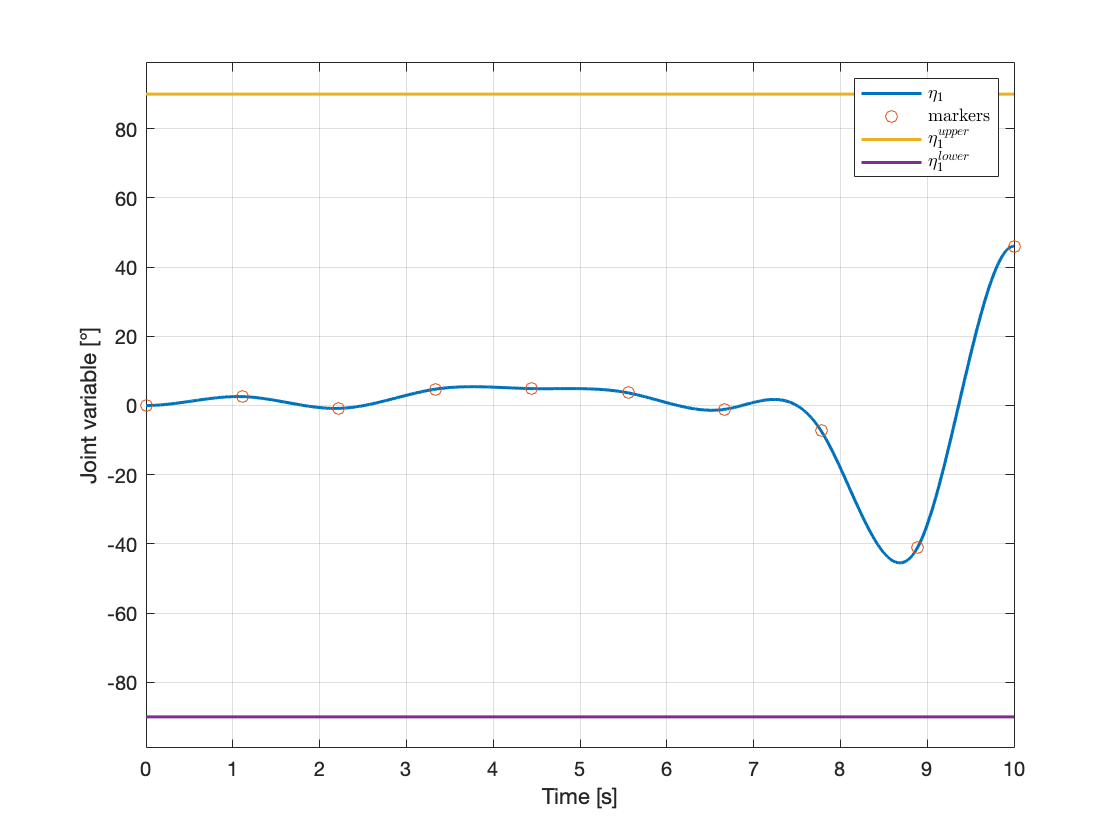

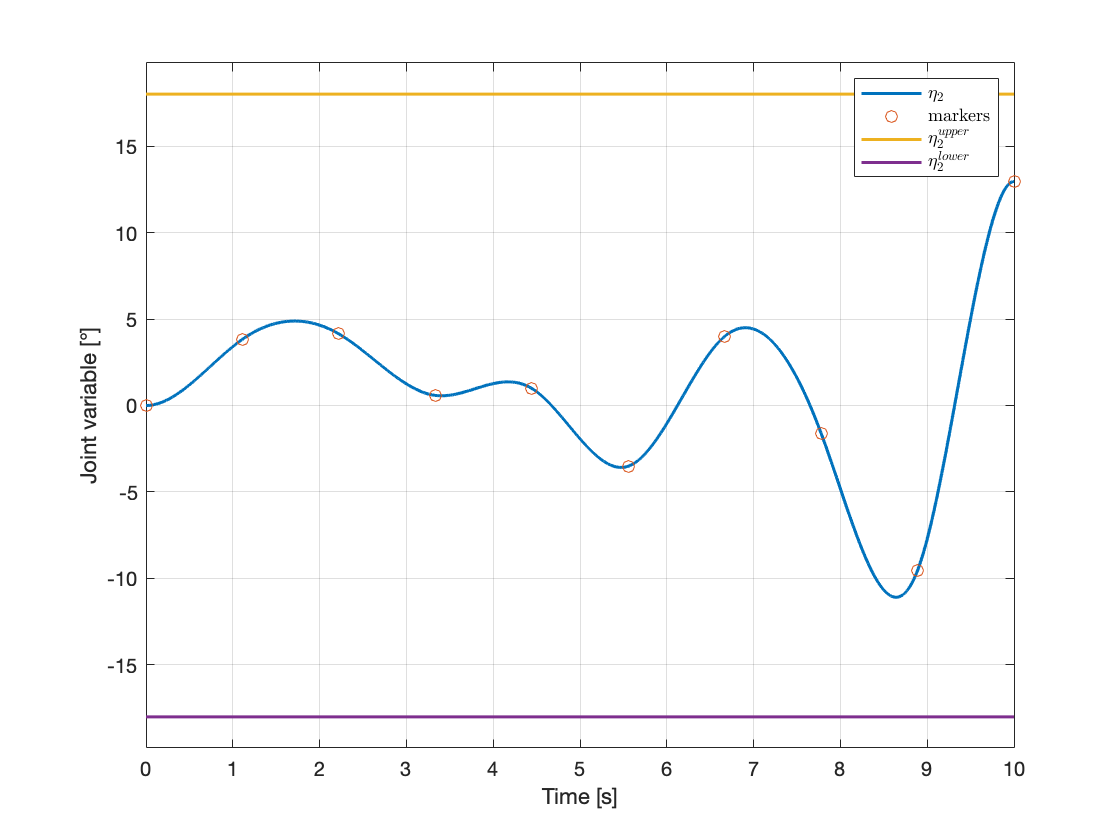

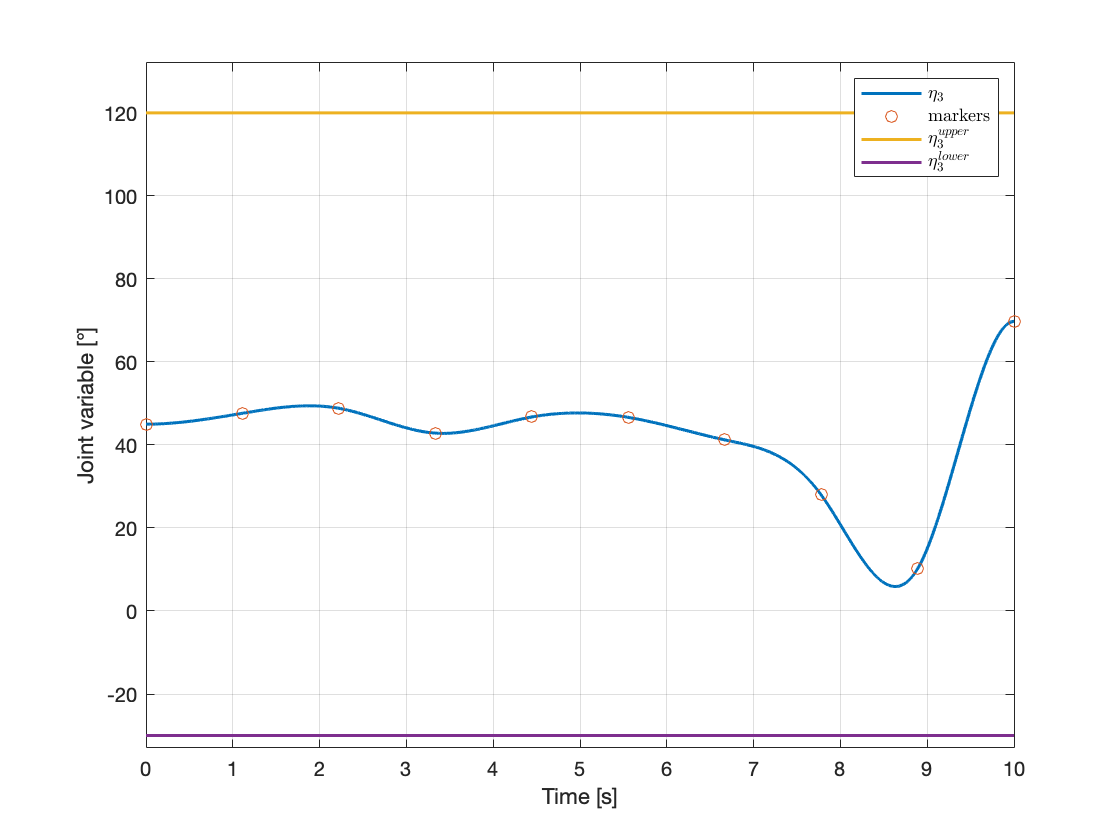

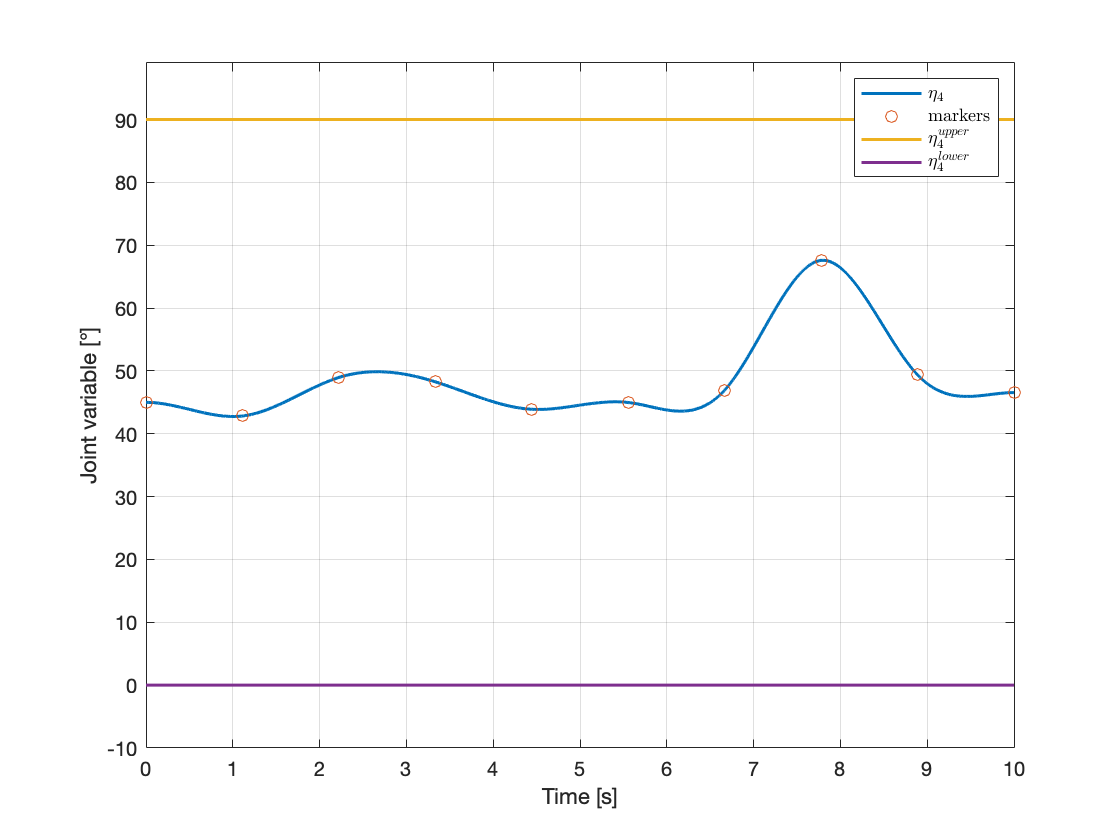

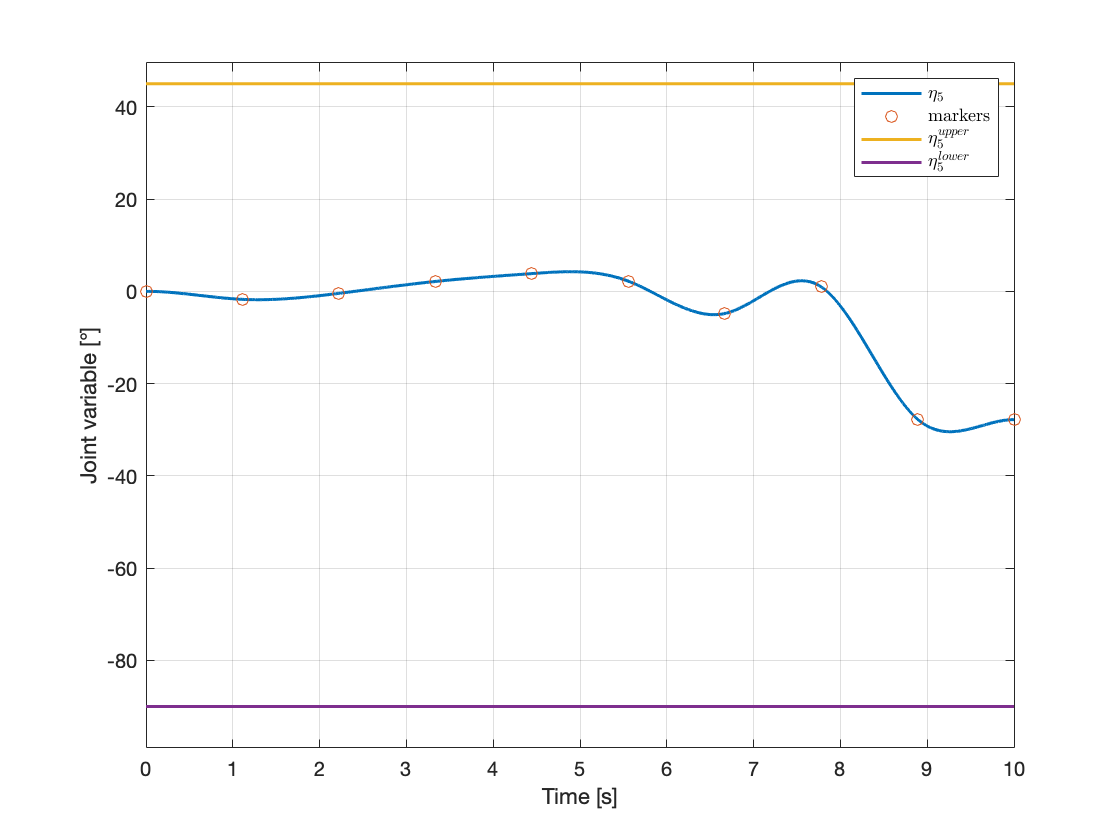

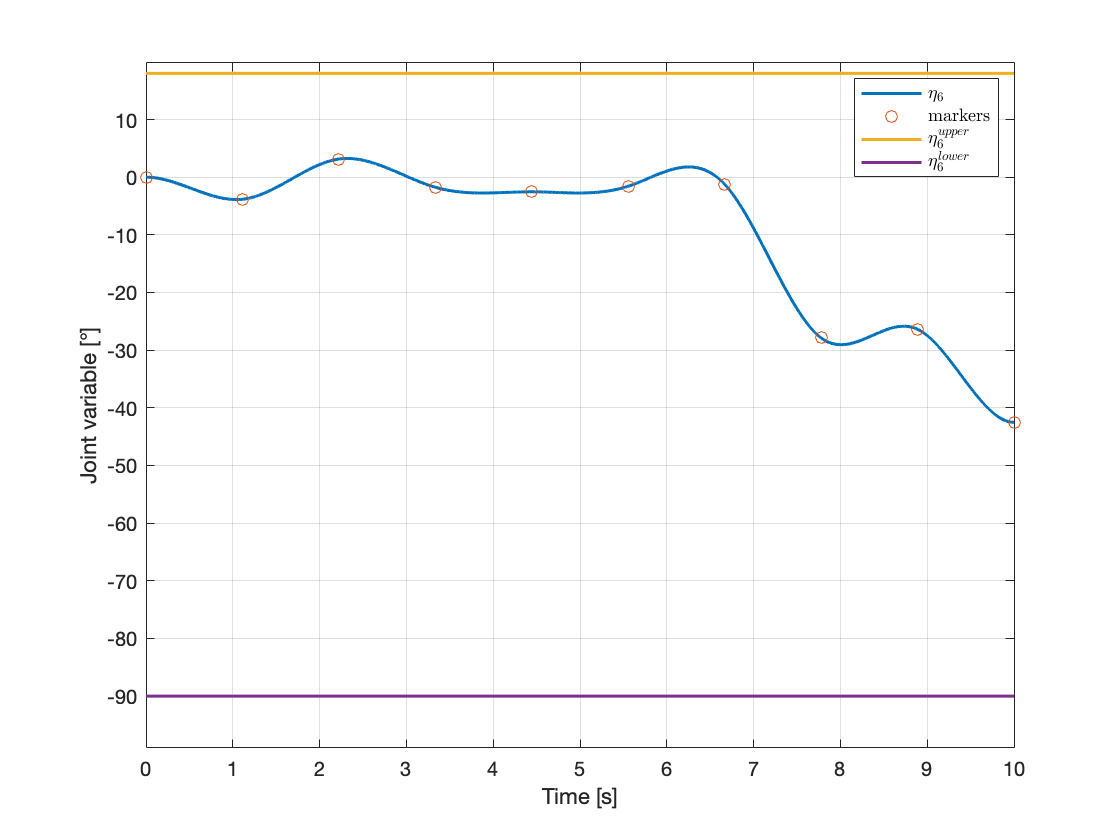

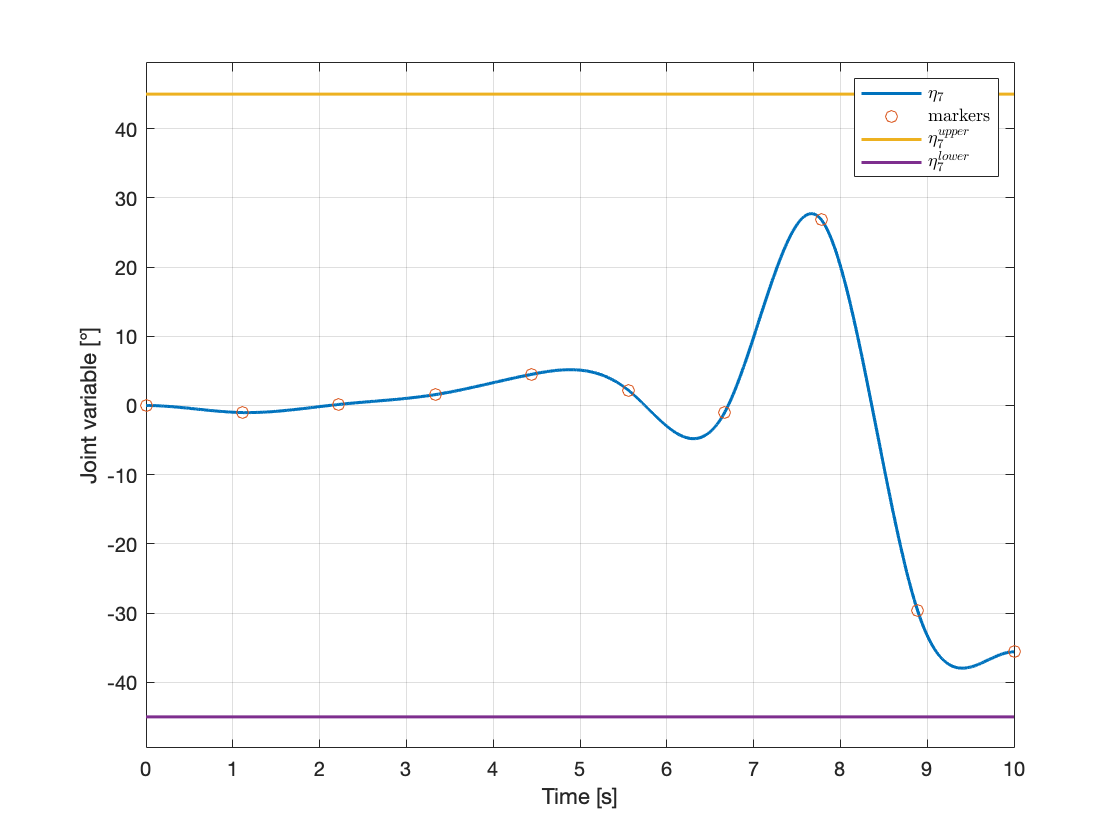

% Clear variables
clear all;
clear global;
close all;
clc;

q_ic = [deg2rad(0); 0; deg2rad(45); deg2rad(45); 0; 0; 0];
num_points = 10;
is_lkf = true;
q_trajectory = generate_trajectory(q_ic, num_points, is_lkf);

run('human_ar_p.m');
m = 4;
global q0;
q0 = q_trajectory(1, 2:8);
% Set sample time for q
set_param('master_thesis_simulink/System/ZOH_q', 'SampleTime', '-1');
output = sim('master_thesis_simulink.slx');

# Plot trajectory

The trajectory is loaded and plotted below.

% Clear variables
clear all;
clear global;
close all;
clc;

% Load trajectories
load('q_trajectory.mat');
load('q_trajectory_lkf.mat');

% Upper saturation     : upper-limit of the joint variables
upper_saturation = [pi/2; pi/10; 2/3*pi; pi/2; pi/4; pi/10; pi/4];
% Lower saturation     : lower-limit of the joint variables
lower_saturation = [-pi/2; -pi/10; -pi/6; 0; -pi/2;  -pi/2; -pi/4];

% Save images
save_images = [true true];
for j = 1 : 2

    if (save_images(j))

        if (j == 1)

            for i = 1:7
            
                fig = figure('Visible', 'off');
                plot(q_trajectory.time, rad2deg(q_trajectory.signals.values(:, i)), 'LineWidth', 1.5);
                hold on;
                plot(q_trajectory.time, rad2deg(upper_saturation(i)*ones(size(q_trajectory.time, 1), 1)), 'LineStyle', '--', 'LineWidth', 1.5);
                hold on;
                plot(q_trajectory.time, rad2deg(lower_saturation(i)*ones(size(q_trajectory.time, 1), 1)), 'LineStyle', '--', 'LineWidth', 1.5);
                xlabel('Time [s]');
                ylabel('Joint variable [°]');
                ylim('padded');
                legend_name{1} = strcat('$\eta_', num2str(i), '$');
                legend_name{2} = strcat('$\eta_', num2str(i), '^{upper}$');
                legend_name{3} = strcat('$\eta_', num2str(i), '^{lower}$');
                legend(legend_name, 'Location', 'NorthOutside', 'Orientation', 'horizontal', 'Box', 'off', 'Interpreter', 'latex', 'FontSize', 26);
                set(gca, 'FontSize', 18);
                grid on;
                eps_name = strcat('Ref_eta', num2str(i));
                saveas(gcf, eps_name, 'epsc');
            end
        else

            for i = 1:7
            
                fig = figure('Visible', 'off');
                plot(q_trajectory_lkf.time, rad2deg(q_trajectory_lkf.signals.values(:, i)), 'LineWidth', 1.5);
                hold on;
                plot(q_trajectory_lkf.time, rad2deg(upper_saturation(i)*ones(size(q_trajectory_lkf.time, 1), 1)), 'LineStyle', '--', 'LineWidth', 1.5);
                hold on;
                plot(q_trajectory_lkf.time, rad2deg(lower_saturation(i)*ones(size(q_trajectory_lkf.time, 1), 1)), 'LineStyle', '--', 'LineWidth', 1.5);
                xlabel('Time [s]');
                ylabel('Joint variable [°]');
                ylim('padded');
                legend_name{1} = strcat('$\eta_', num2str(i), '$');
                legend_name{2} = strcat('$\eta_', num2str(i), '^{upper}$');
                legend_name{3} = strcat('$\eta_', num2str(i), '^{lower}$');
                legend(legend_name, 'Location', 'NorthOutside', 'Orientation', 'horizontal', 'Box', 'off', 'Interpreter', 'latex', 'FontSize', 26);
                set(gca, 'FontSize', 18);
                grid on;
                eps_name = strcat('Ref_eta', num2str(i), '_lkf');
                saveas(gcf, eps_name, 'epsc');
            end
        end
    end

    % Clear 'fig' variable
    clear fig;
end

% Plot trajectory
figure();
sgtitle('TRAJECTORY');
for i = 1:7
            
    subplot(3,3,i)
    plot(q_trajectory.time, rad2deg(q_trajectory.signals.values(:, i)));
    hold on;
    plot(q_trajectory.time, rad2deg(upper_saturation(i)*ones(size(q_trajectory.time, 1), 1)), 'LineStyle', '--');
    hold on;
    plot(q_trajectory.time, rad2deg(lower_saturation(i)*ones(size(q_trajectory.time, 1), 1)), 'LineStyle', '--');
    xlabel('Time [s]');
    ylabel('Joint variable [°]');
    legend_name{1} = strcat('$\eta_', num2str(i), '$');
    legend_name{2} = strcat('$\eta_', num2str(i), '^{upper}$');
    legend_name{3} = strcat('$\eta_', num2str(i), '^{lower}$');
    legend(legend_name, 'Interpreter', 'latex');
    grid on;
end

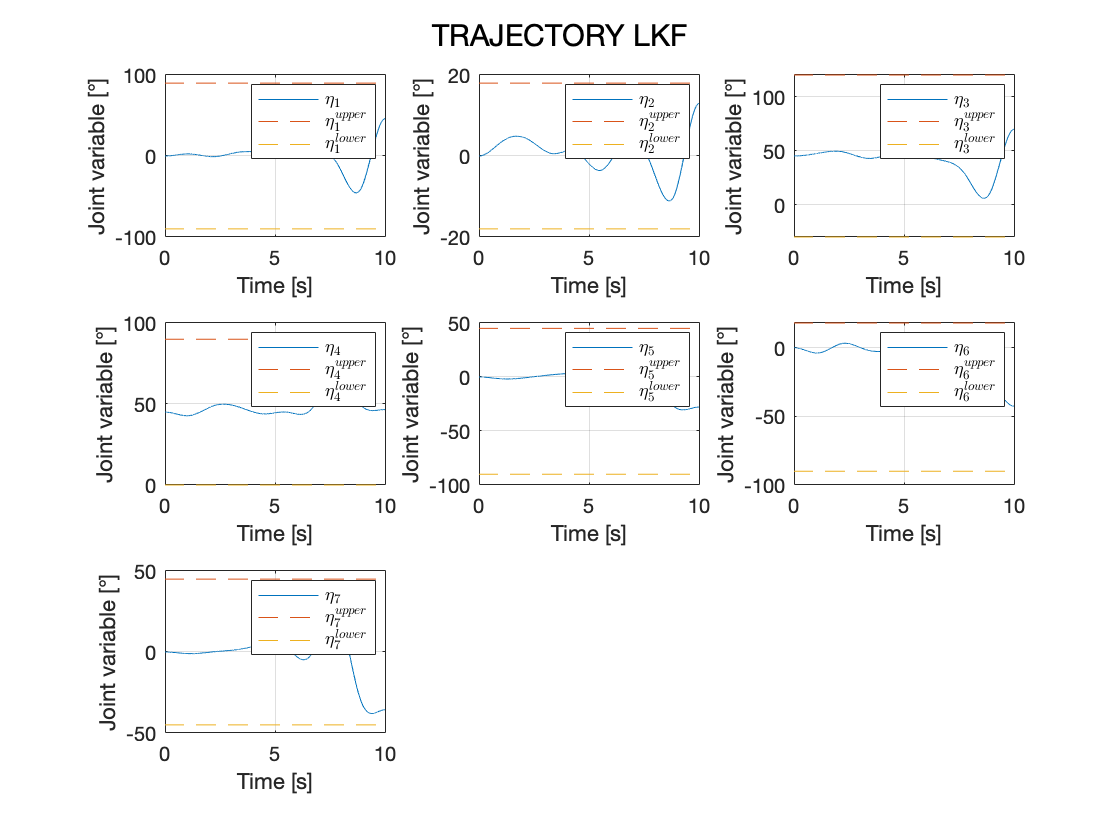

% Plot trajectory_lkf
figure();
sgtitle('TRAJECTORY LKF');
for i = 1:7

    subplot(3,3,i);
    plot(q_trajectory_lkf.time, rad2deg(q_trajectory_lkf.signals.values(:, i)));
    hold on;
    plot(q_trajectory_lkf.time, rad2deg(upper_saturation(i)*ones(size(q_trajectory_lkf.time, 1), 1)), 'LineStyle', '--');
    hold on;
    plot(q_trajectory_lkf.time, rad2deg(lower_saturation(i)*ones(size(q_trajectory_lkf.time, 1), 1)), 'LineStyle', '--');
    xlabel('Time [s]');
    ylabel('Joint variable [°]');
    legend_name{1} = strcat('$\eta_', num2str(i), '$');
    legend_name{2} = strcat('$\eta_', num2str(i), '^{upper}$');
    legend_name{3} = strcat('$\eta_', num2str(i), '^{lower}$');
    legend(legend_name, 'Interpreter', 'latex');
    grid on;
end

# Mex functions generations

% Clear variables
clear all;
clear global;
close all;
clc;

% Run Human arm parameters
run('human_ar_p.m');

% Plausible combinations of number of markers
set_combinations_m3 = [0 1 2;
                       1 0 2];
 set_combinations_m4 = [0 2 2;
                        1 0 3;
                        1 1 2;
                        2 0 2];
 set_combinations_m5 = [1 2 2];
 set_combinations = [set_combinations_m3;
                     set_combinations_m4;
                     set_combinations_m5];

% Number of combinations
number_combinations = size(set_combinations, 1);

for i = 1:number_combinations

    % Number of markers on the shoulder, forearm, hand
    shoulder_num = set_combinations(i, 1); 
    forearm_num = set_combinations(i, 2); 
    hand_num = set_combinations(i, 3);

    f_J = mex_generation(shoulder_num, forearm_num, hand_num, 'true');
end

Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building

# Preliminary simulation

#### FORWARD KINEMATICS


$$\mathbf{p} = \pmatrix{\mathbf{p_{1}} \cr \mathbf{p_{2}} \cr .. \cr \mathbf{p_{m}}} = \pmatrix{\mathbf{\Phi_1} \cr \mathbf{\Phi_2} \cr ..  \cr \mathbf{\Phi_m} } =  \mathbf{\Phi}(\mathbf{\eta})\quad,\qquad \mathbf{p_i} = \mathbf{\Phi_i} = \left\{\begin{array}{c}
         \mathbf{\Phi}_{Sh}\left(\mathbf{\eta}_{1-3}, \mathbf{p_i}^{Sh}\right), \quad i \in \mathcal{S}  \\
         \mathbf{\Phi}_{Fo}\left(\mathbf{\eta}_{1-4}, \mathbf{p_i}^{El}\right), \quad i \in \mathcal{F}\\
         \mathbf{\Phi}_{Ha}\left(\mathbf{\eta}, \mathbf{p_h}^{Wr}\right), \quad i \in \mathcal{H}
    \end{array}
\right. \quad i = 1,\dots,m$$


####  DIFFERENTIAL KINEMATICS


$$ \dot{\mathbf{p}} = \pmatrix{\dot{\mathbf{p_{1}}} \cr \dot{\mathbf{p_{2}}} \cr .. \cr \dot{\mathbf{p_{m}}}} = \pmatrix{\mathbf{J_1}(\mathbf{\eta}) \cr \mathbf{J_2}(\mathbf{\eta}) \cr ..  \cr \mathbf{J_m}(\mathbf{\eta}) } \cdot \dot{\mathbf{\eta}} = \mathbf{J(\eta)}\cdot\dot{\mathbf{\eta}}$$


Find suitable combinations of number of markers. Given a trajectory for the joint-space, $\mathbf{\eta}^{ref}$, and a given combination of markers, in terms of number of markers on the shoulder, forearm and hand, it is considered a good combination if the jacobian $\mathbf{J}\left(\mathbf{\eta}\right)$ is not singular and is not close to be singular $\forall \mathbf{\eta} \in \mathbf{\eta}^{ref}$. The percentages of singular, non-singular and quasi-singualar points along the trajectory is computed. This is repeated 20 times foreach markers' combination.

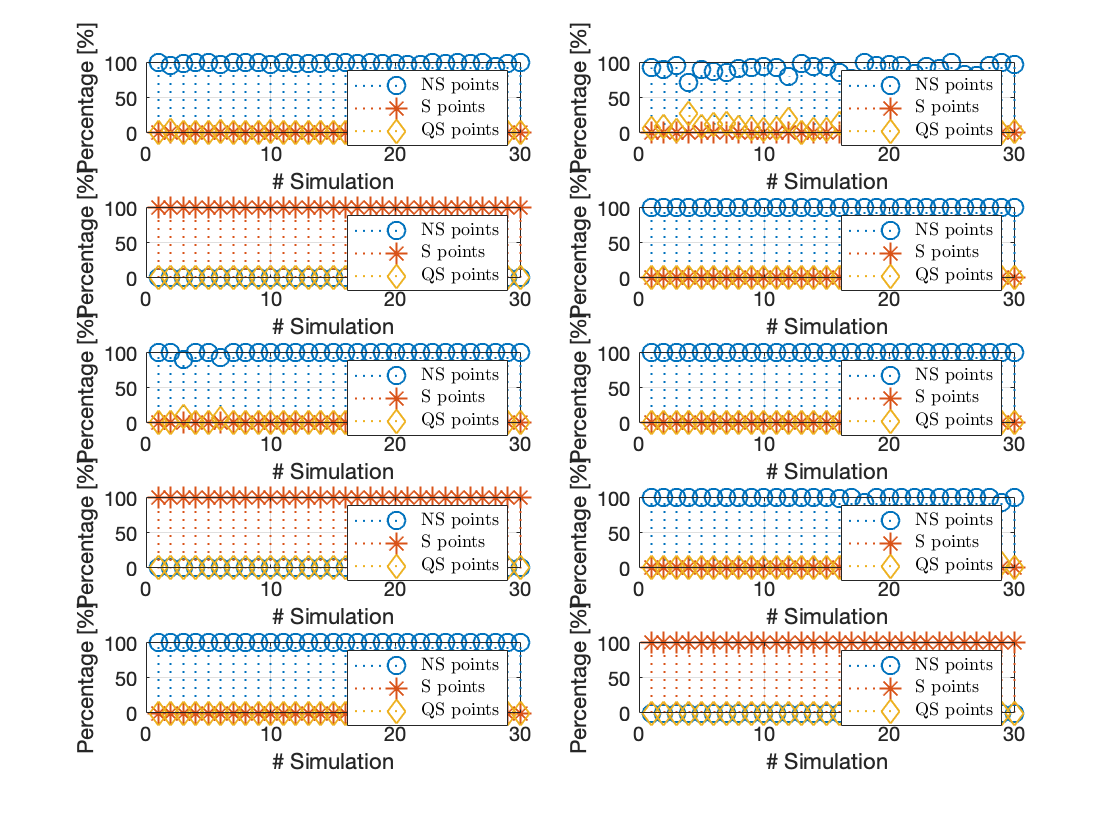

% Clear variables
clear all;
clear global;
close all;
clc;

% Load trajectory
load('q_trajectory.mat');

% Run Human arm parameters
run('human_ar_p.m');

% Plausible combinations of number of markers
set_combinations_m3 = [0 1 2;
                       1 0 2;
                       1 1 1];
set_combinations_m4 = [0 2 2;
                       1 0 3;
                       1 1 2;
                       1 2 1;
                       2 0 2];
set_combinations_m5 = [1 2 2;
                       2 2 1];
set_combinations = [set_combinations_m3;
                    set_combinations_m4;
                    set_combinations_m5];

% Number of simulations foreach combination
number_simulations = 30;

% Save markers of the non-singular combinations [3 7 10]
save_markers_nonSingular_combinations = [false false false];
% Run preliminary simulation
preliminary_simulation(set_combinations, number_simulations, q_trajectory, save_markers_nonSingular_combinations);

# Save other set of markers

% Clear variables
clear all;
clear global;
close all;
clc;

% Folders
simulations_folders = ['S0_F1_H2';
                       'S0_F2_H2';
                       'S1_F0_H2';
                       'S1_F0_H3';
                       'S1_F1_H2';
                       'S1_F2_H2';
                       'S2_F0_H2'];

for i = 1:size(simulations_folders, 1)

    save_markers(simulations_folders(i, :));
end

6th combination already computed


# Chosen set of markers --> S1 F1 H2

In the following simulations only one set of markers is considered (best set among the 20 simulations considering the $6^{th}$ combination (1 on  the SHOULDER, 1 on the FOREARM, 2 on the HAND). The simscape model is run.

% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers and set them in Simulink
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Comment/Uncomment blocks
set_param('master_thesis_simulink/System', 'commented', 'off');
set_param('master_thesis_simulink/Ros2Matlab', 'commented', 'on');
set_param('master_thesis_simulink/Experiments', 'commented', 'on');
set_param('master_thesis_simulink/System/LS', 'commented', 'on');
set_param('master_thesis_simulink/System/EKF', 'commented', 'on');
set_param('master_thesis_simulink/System/LKF', 'commented', 'on');
set_param('master_thesis_simulink/System/Noisy p', 'commented', 'on');
set_param('master_thesis_simulink/System/Noisy pdot', 'commented', 'on');
set_param('master_thesis_simulink/System/ZOH', 'commented', 'on');
set_param('master_thesis_simulink/System/ZOH1', 'commented', 'on');

% Simulink parameters
q0 = q_trajectory.signals.values(1,:);
set_param('master_thesis_simulink', 'StopTime', '10');

% Run Simulink
sim('master_thesis_simulink.slx');

% Remove blocks
remove_blocks_simulink(size(markers_shoulder, 2), size(markers_forearm, 2), size(markers_hand, 2));

# Least Squares

Considering the equation $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) + \mathbf{n_{\dot{p}}}\left(t\right), \quad \mathbf{n_{\dot{p}}}\left(t\right) \sim \mathcal{N}\left(0, \mathbf{N_{\dot{p}}}\right)$, one can simply estimate the joint variables by integrating $\hat{\dot{\mathbf{\eta}}}^{LS}\left(t\right)$, leading to $\hat{\mathbf{\eta}}^{LS}\left(t\right)$, where 


$$\hat{\dot{\mathbf{\eta}}}^{LS}\left(t\right) = \mathbf{J}^{\dagger}_L\left(\hat{\mathbf{\eta}}^{LS}\left(t\right)\right)\cdot\dot{\mathbf{p}}\left(t\right)$$


Hence, there are 2 parmeters to decide:

- a --> Initial estimate $\hat{\mathbf{\eta}}^{LS}\left(0\right)$

- b --> Noisy $ \dot{\mathbf{p}}\left(t\right)$ vs Deterministic $ \dot{\mathbf{p}}\left(t\right)$

## $6^{th}$ Combination --> NON-SINGULARITIES

First, J full-columnn rank is considered (6th Combination) --> Unique LS solution

### Scenario 1

### 1.a --> $\hat{\mathbf{\eta}}^{LS}\left(0\right) =\mathbf{\eta}\left(0\right)$

### 1.b --> Deterministic $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) $

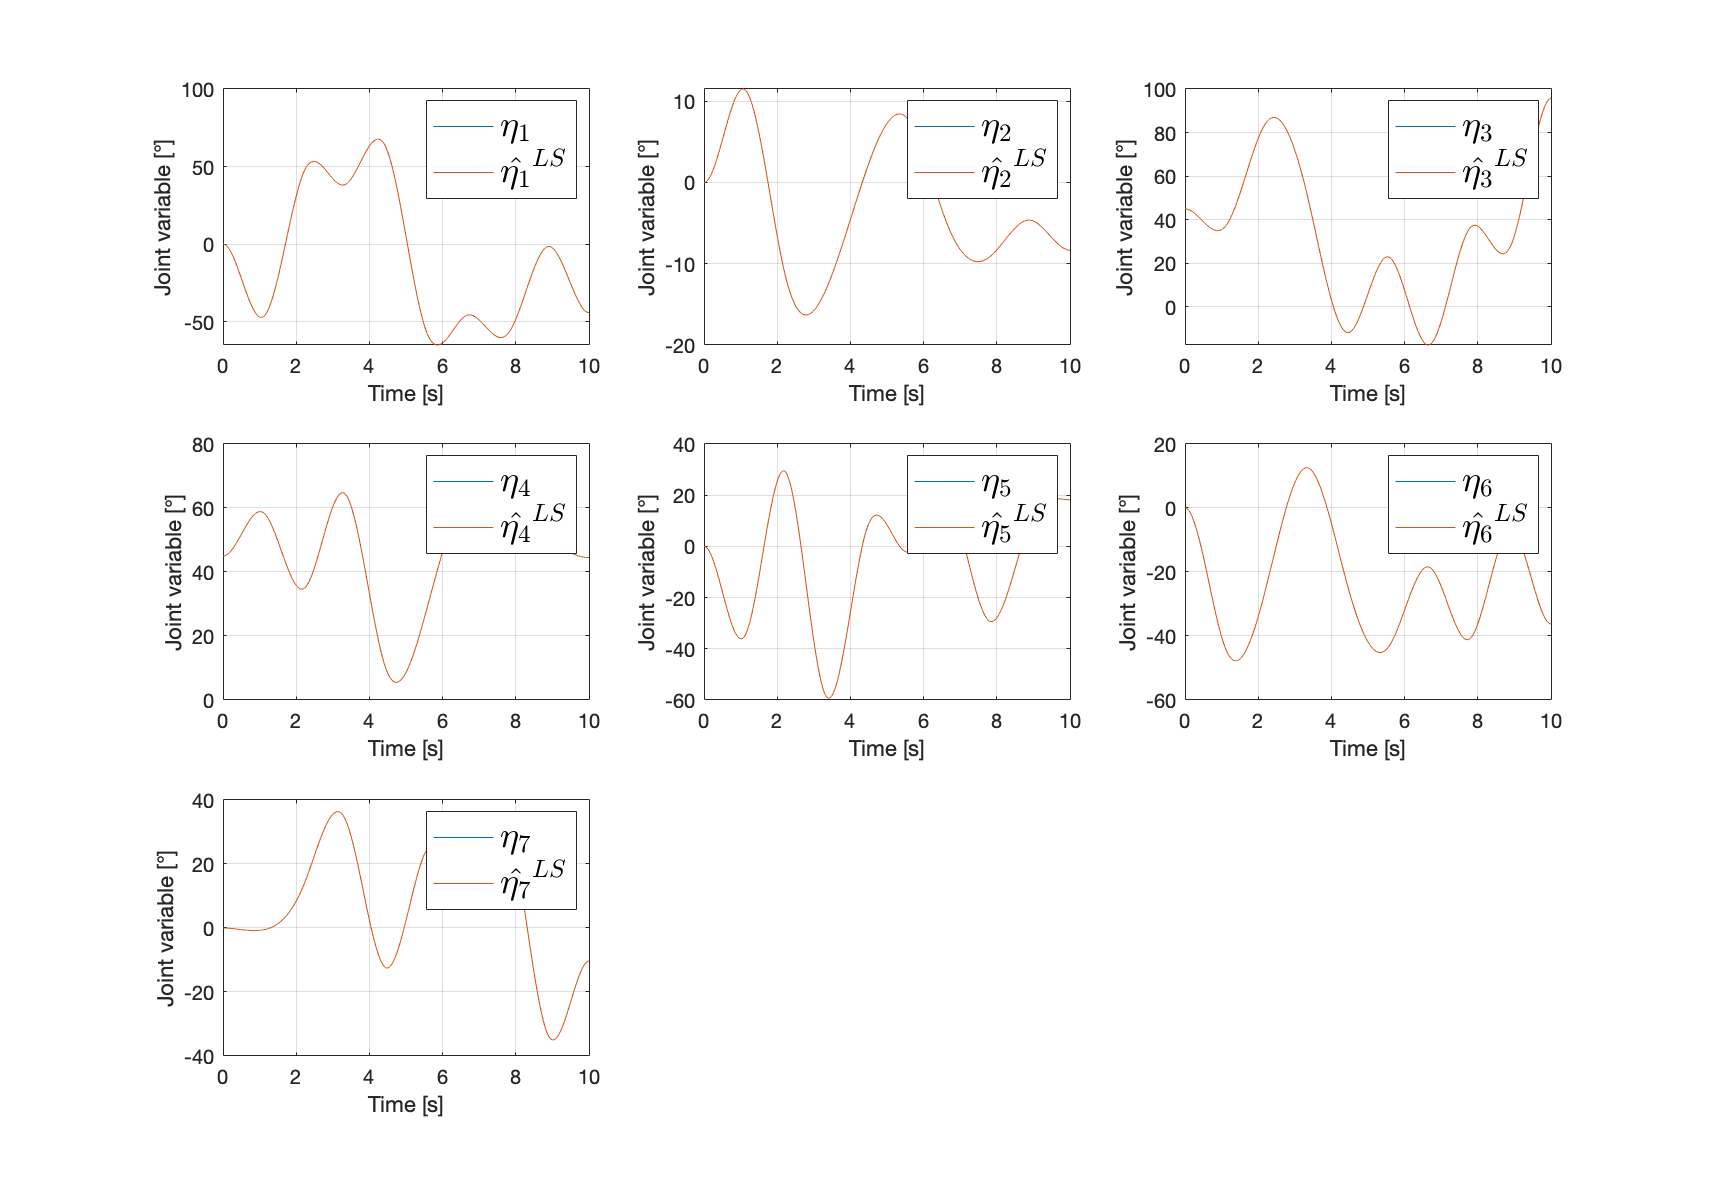

The RMSE of scenario 1 is 1.3884e-07


% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global q0_LS;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

% Results
initial_estimate = q0;
covariance_n_pdot = zeros(3*m, 3*m);
LS(initial_estimate, covariance_n_pdot, 1, directory);

### Scenario 2

### 1.a --> $\hat{\mathbf{\eta}}^{LS}\left(0\right) \neq \mathbf{\eta}\left(0\right)$

### 1.b --> Deterministic $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) $

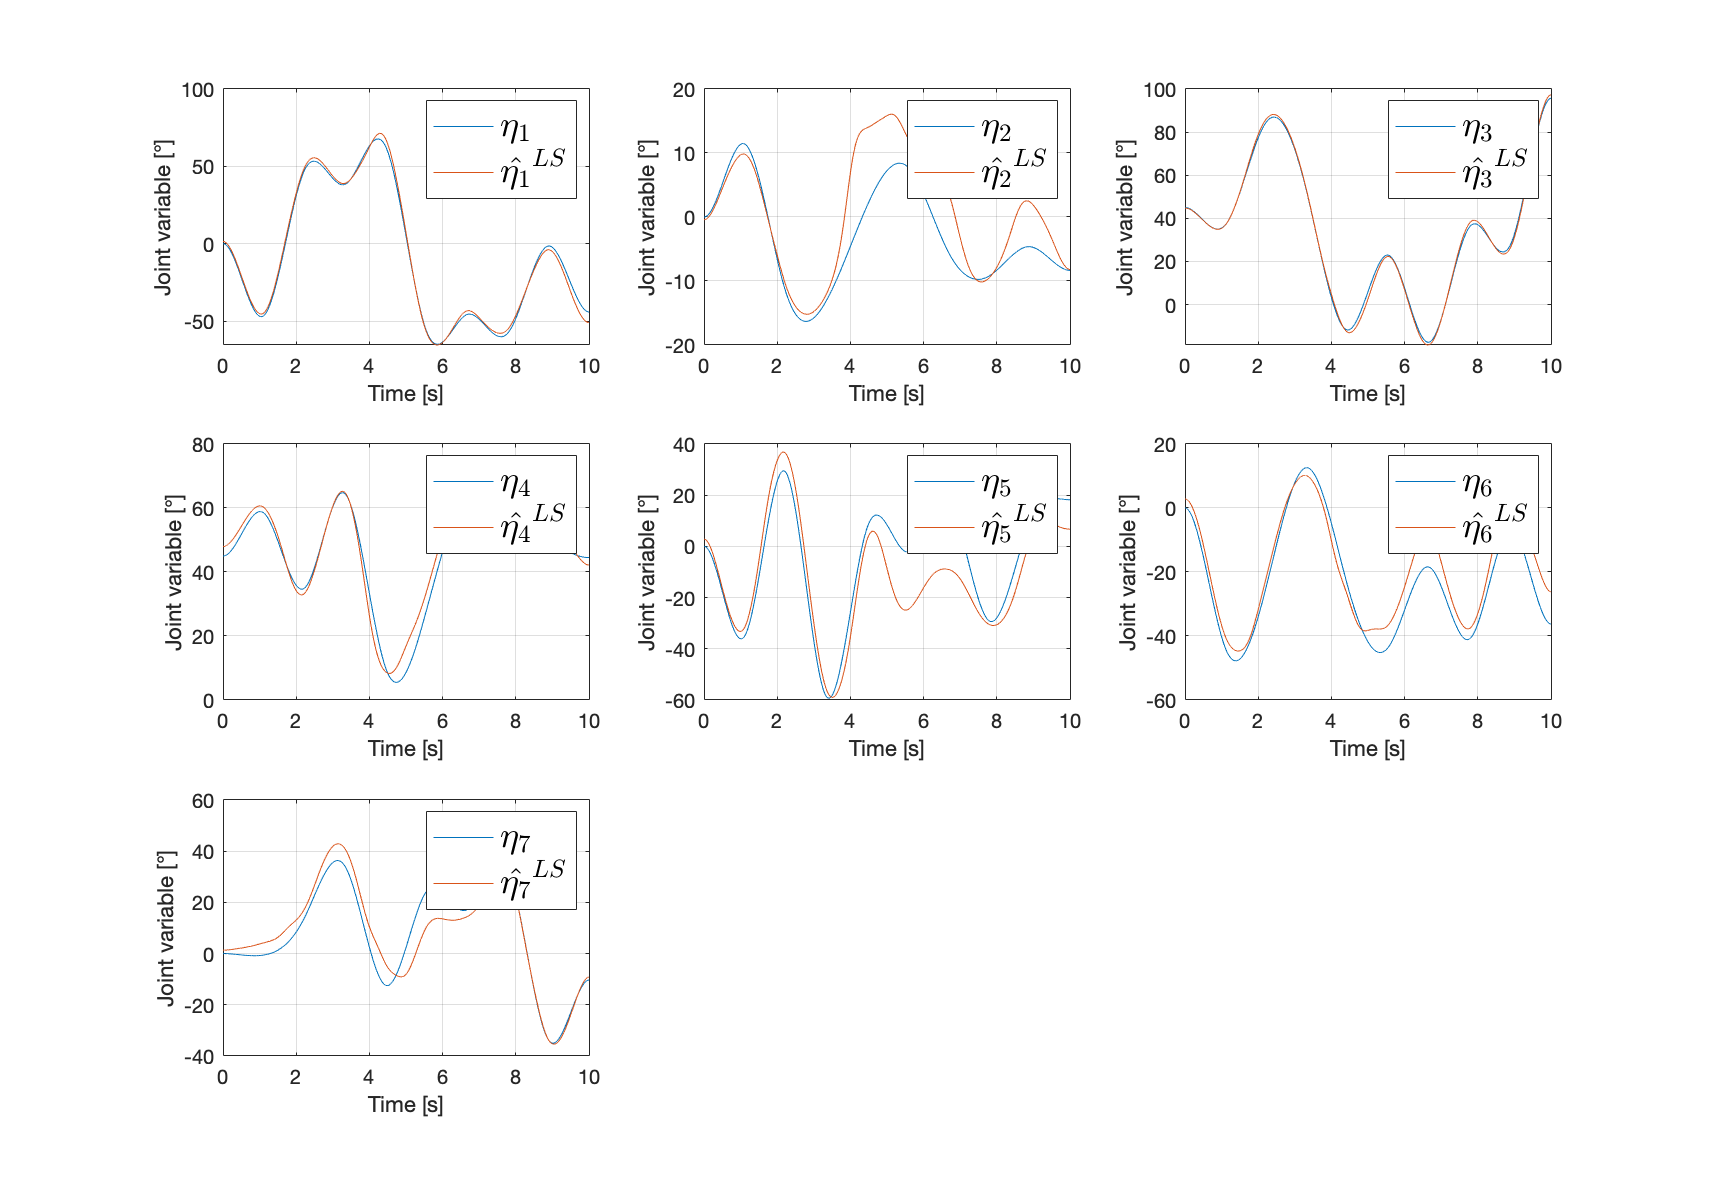

The RMSE of scenario 2 is 0.50107


% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global q0_LS;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

% Results
initial_estimate_deg = normrnd(rad2deg(q0), 2*ones(size(q0, 1), 1));
initial_estimate = deg2rad(initial_estimate_deg);
covariance_n_pdot = zeros(3*m, 3*m);
LS(initial_estimate, covariance_n_pdot, 2, directory);

### Scenario 3

### 1.a --> $\hat{\mathbf{\eta}}^{LS}\left(0\right) = \mathbf{\eta}\left(0\right)$

### 1.b --> Noisy $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) + \mathbf{n_{\dot{p}}}\left(t\right)$

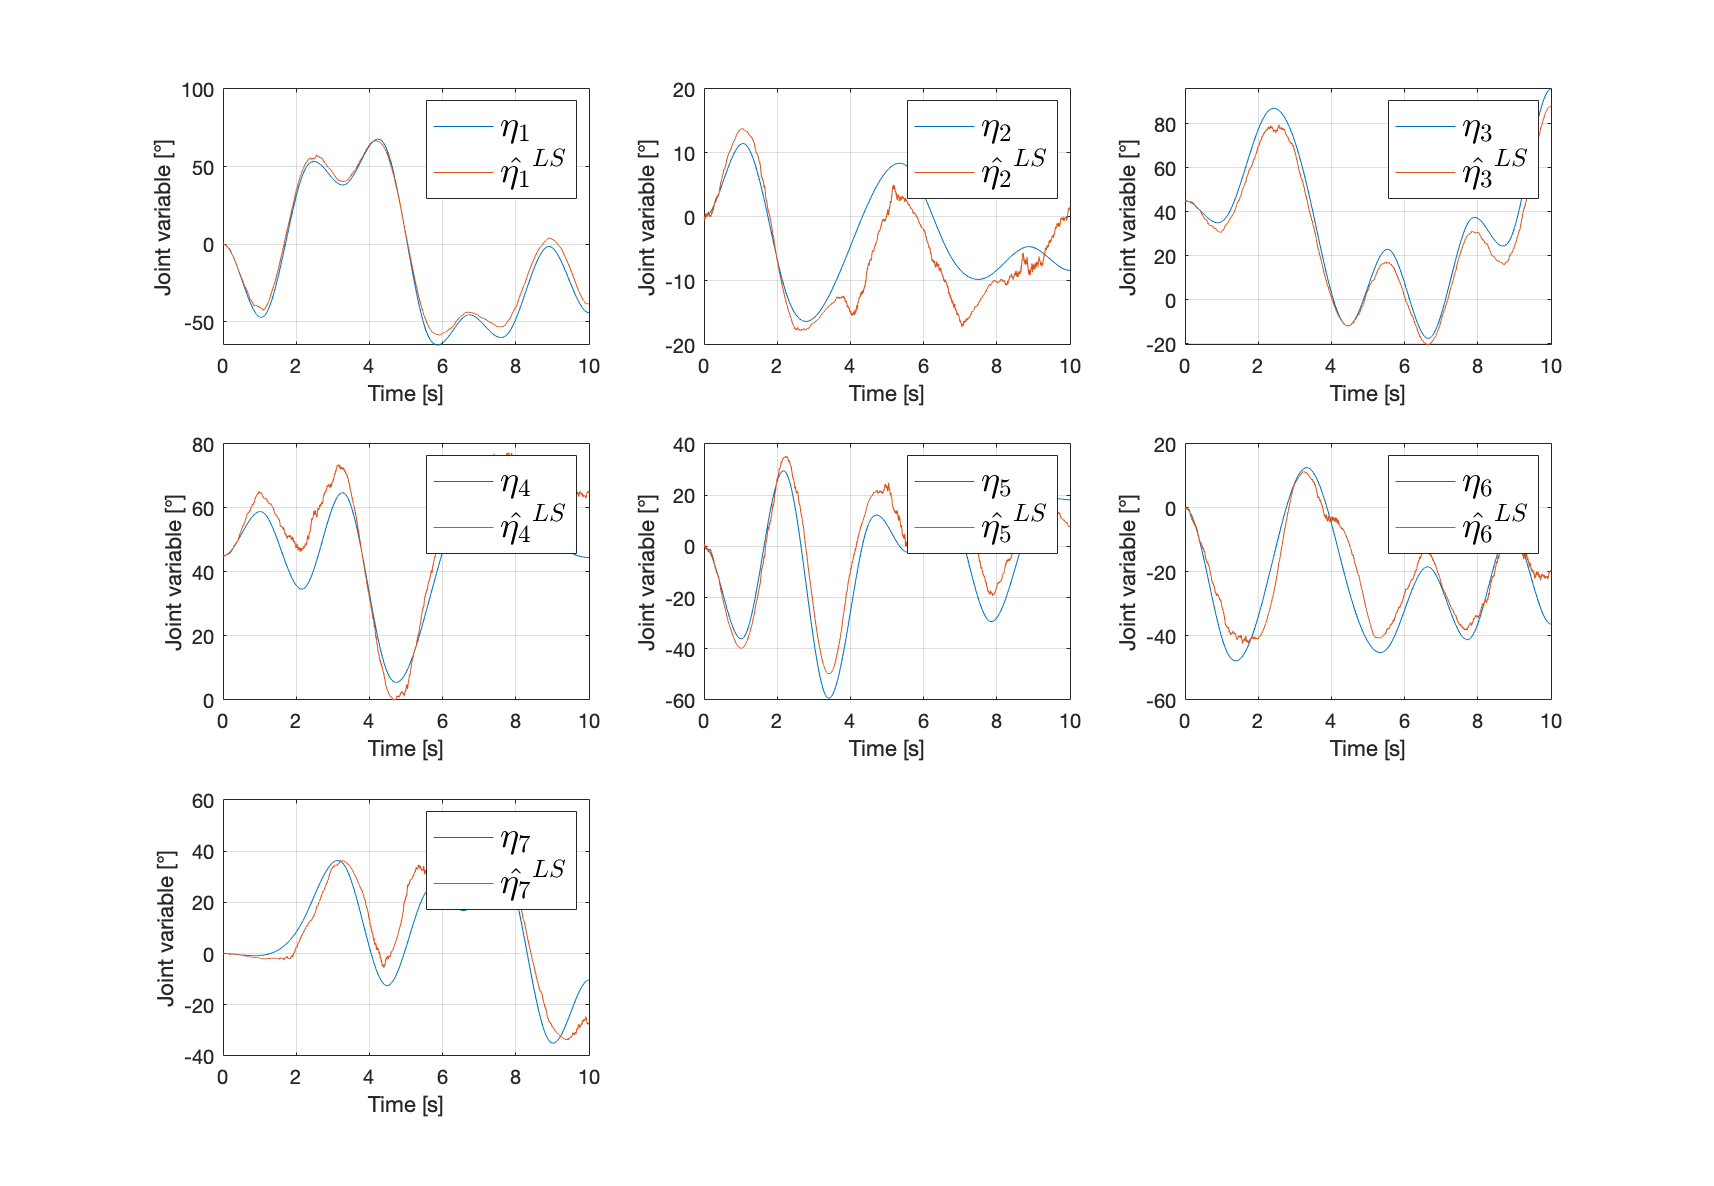

The RMSE of scenario 3 is 0.56446


% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global q0_LS;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

% Results
initial_estimate = q0;
covariance_n_pdot = 0.0285 * diag(ones(m*3, 1));
LS(initial_estimate, covariance_n_pdot, 3, directory);

### Scenario 4

### 1.a --> $\hat{\mathbf{\eta}}^{LS}\left(0\right) \neq\mathbf{\eta}\left(0\right)$

### 1.b --> Noisy $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) + \mathbf{n_{\dot{p}}}\left(t\right)$

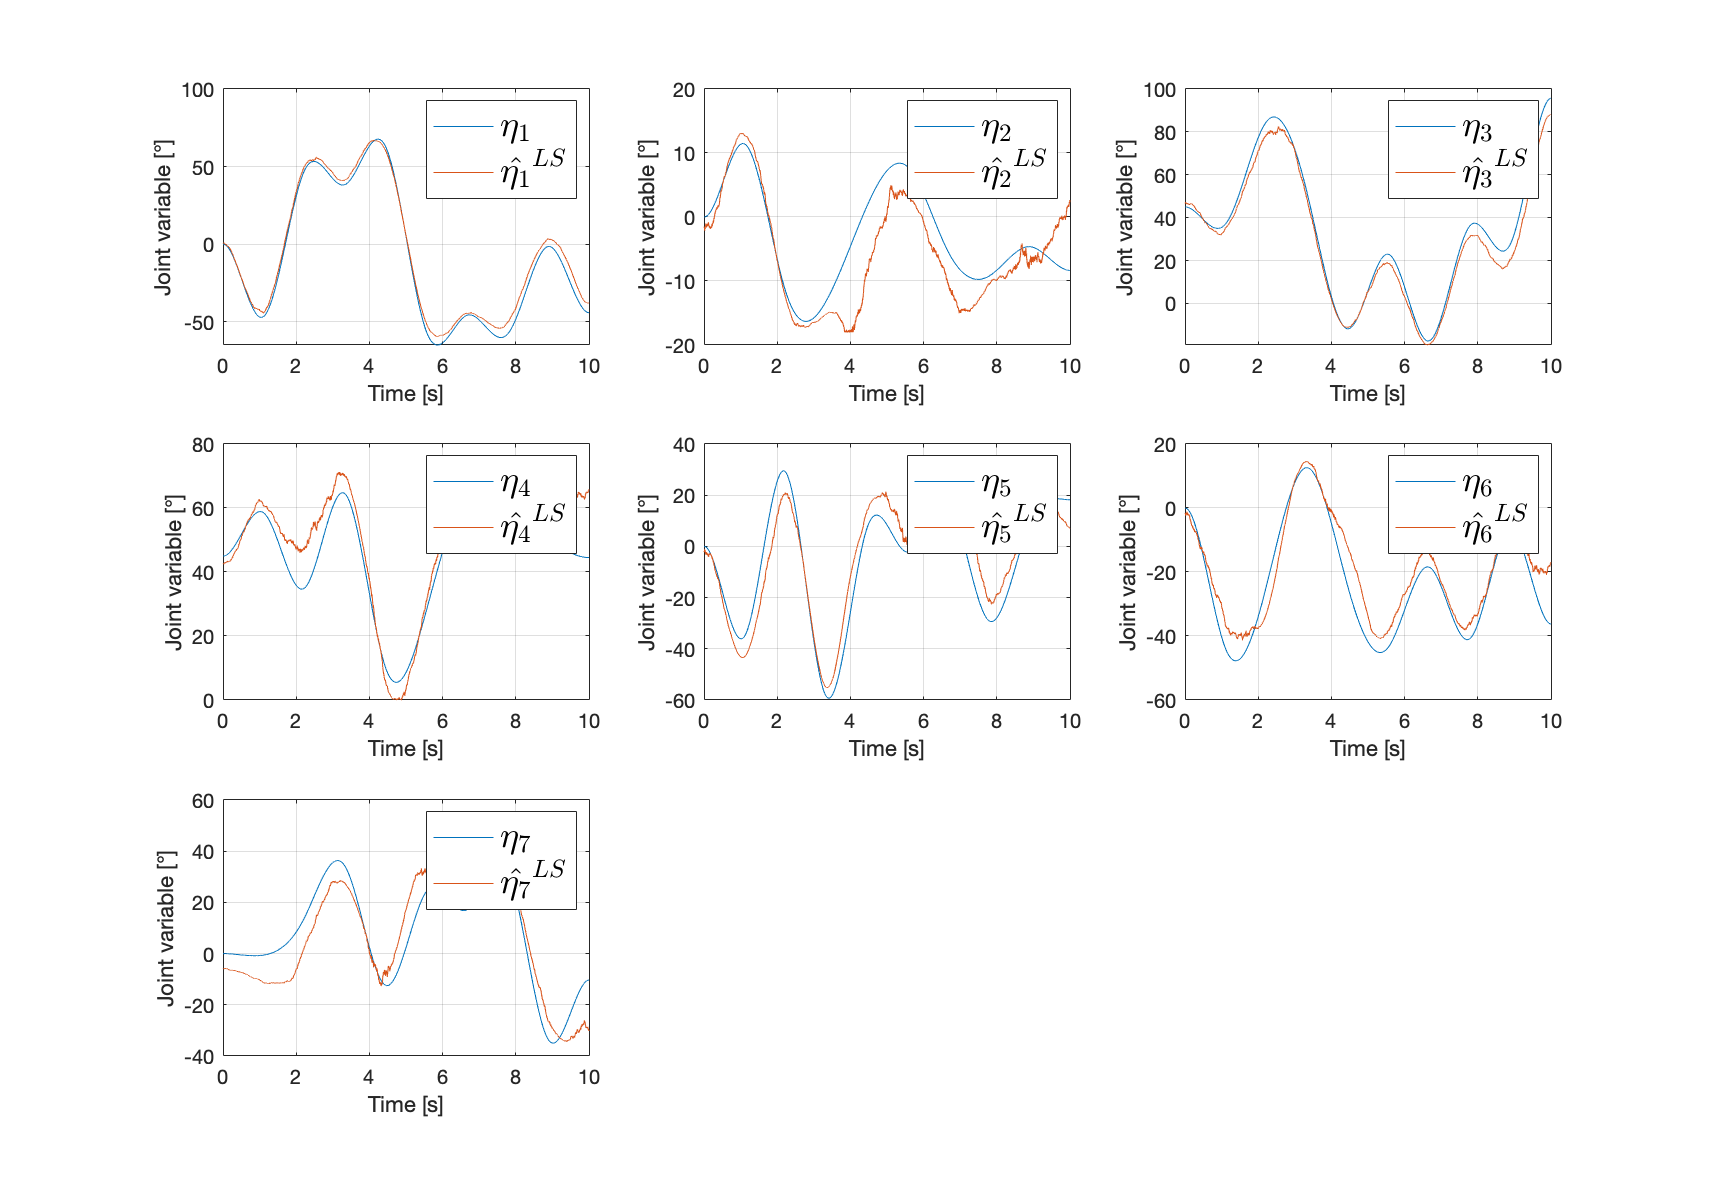

The RMSE of scenario 4 is 0.54955


% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global q0_LS;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

% Results
initial_estimate_deg = normrnd(rad2deg(q0), 2*ones(size(q0, 1), 1));
initial_estimate = deg2rad(initial_estimate_deg);
N_pdot = 0.0285 * diag(ones(m*3, 1));
LS(initial_estimate, N_pdot, 4, directory);

## $7^{th}$ Combination --> SINGULARITIES

Secondly, J singular is considered (7th Combination) --> Multiple LS solution

### Scenario 5

### 5.a --> $\hat{\mathbf{\eta}}^{LS}\left(0\right) =\mathbf{\eta}\left(0\right)$

### 5.b --> Deterministic $ \dot{\mathbf{p}}\left(t\right)= \mathbf{J}\left(\mathbf{\eta}\left(t\right)\right)\cdot\dot{\mathbf{\eta}}\left(t\right) $

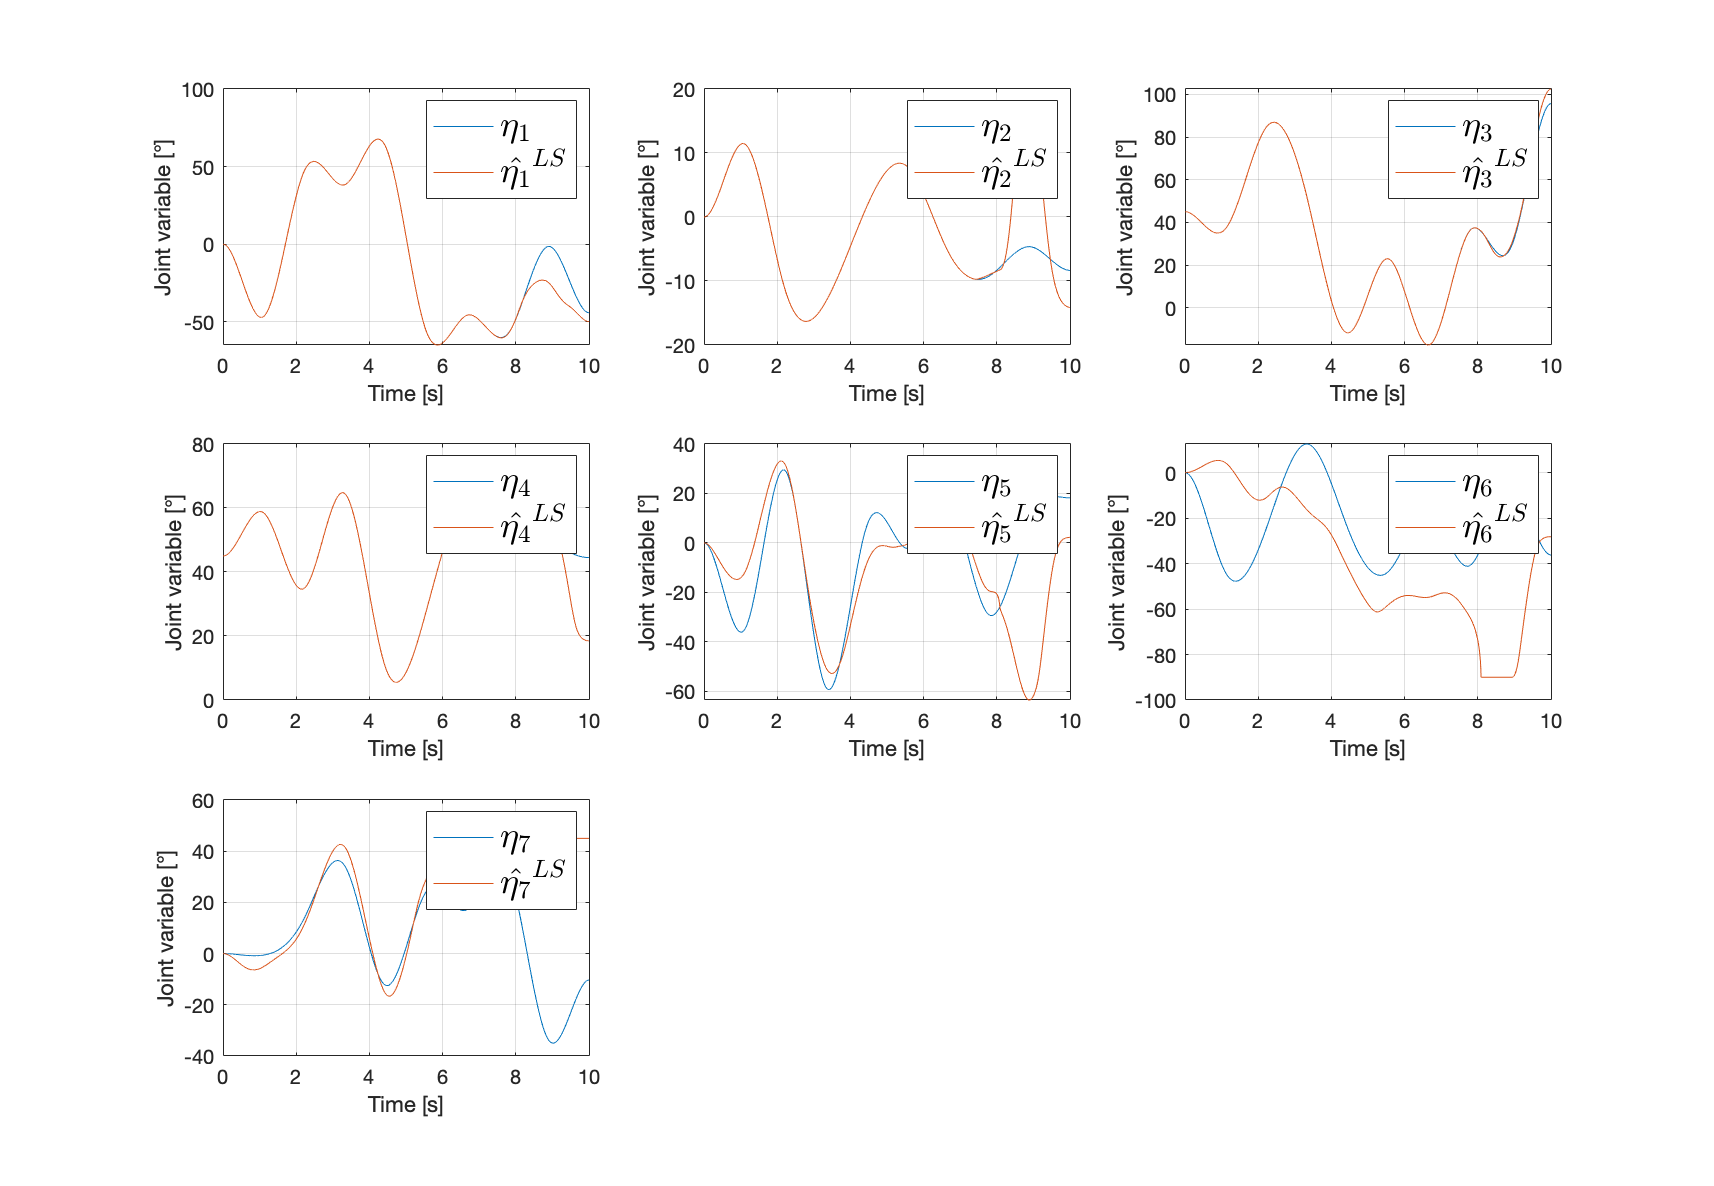

The RMSE of scenario 5 is 0.8221


% Clear variables
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global q0_LS;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_7th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2:3);
markers_hand = markers_best(:, 4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

% Results
initial_estimate = q0;
N_pdot = zeros(3*m, 3*m);
LS(initial_estimate, N_pdot, 5, directory);

# KALMAN FILTER 

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time $T_s$ = 10ms is chosen.


$$\begin{cases}
\mathbf{\eta}_{k+1} = \textbf{f}(\mathbf{\eta}_k,\dot{\mathbf{p}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{\eta}_k) \\
\end{cases}\\
\textbf{f} = \mathbf{\eta}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{\eta}_k)\cdot \dot{\mathbf{p}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{\eta}_k + T_s  \cdot  \frac{\mathbf{k_1}}{2})\cdot \dot{\mathbf{p}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{\eta}_k + T_s  \cdot  \frac{\mathbf{k_2}}{2})\cdot \dot{\mathbf{p}}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{\eta}_k + T_s  \cdot  \mathbf{k_3})\cdot \dot{\mathbf{p}}_k$$


## 2.  Discrete Linear model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta \eta}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta \eta}_k + \mathbf{G}\cdot \mathbf{\Delta}\dot{\mathbf{p}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{J}\cdot\mathbf{\Delta \eta}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta \eta}_{k} = \mathbf{\eta}_k - \bar{\mathbf{\eta}} \\
\mathbf{\Delta \dot{\mathbf{p}}_{k} = \dot{\mathbf{p}}_{k} - \bar{\dot{\mathbf{p}}}\\
\mathbf{\Delta \mathbf{p}_{k} = \mathbf{p}_{k} - \bar{\mathbf{p}}
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \frac{\partial\mathbf{f}}{\partial \mathbf{\eta}}|_{\left(\bar{\mathbf{\eta}},\bar{\dot{\mathbf{p}}}\right)}\\
\mathbf{G} = \frac{\partial\mathbf{f}}{\partial \dot{\mathbf{p}}}|_{\left(\bar{\mathbf{\eta}},\bar{\dot{\mathbf{p}}}\right)}\\
\mathbf{J} = \frac{\partial\mathbf{\Phi}}{\partial \mathbf{\eta}}|_{\left(\bar{\mathbf{\eta}},\bar{\dot{\mathbf{p}}}\right)}$$


The values for $\Delta\hat{\mathbf{\eta}}_0^{KF}$, $\mathbf{P}_{0\mid 0}$, $\mathbf{Q}$, $\mathbf{R}$, $\mathbf{N_{\dot{p}}$ and $\left(\bar{\mathbf{\eta}},\bar{\dot{\mathbf{p}}}\right)$must be decided. 

- $\left(\bar{\mathbf{\eta}},\bar{\dot{\mathbf{p}}}\right)$ is chosen as $\bar{\mathbf{\eta}} = \mathbf{\eta}^{ref}_{lkf}\left(0\right)$, $\bar{\dot{\mathbf{p}}} = \mathbf0$.

- $\mathbf{N_{\dot{p}}} = 10^{-2}\cdot\sigma_{\dot{\mathbf{p}}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\dot{\mathbf{p}}}^2 = 0.0285\ \left(m/s\right)^2$.

- $\Delta\hat{\mathbf{\eta}}_0^{KF} \neq \mathbf 0$.

- 
$$\mathbf{P}_{0\mid 0} = \sigma_{\mathbf{P}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\mathbf{P}}^2 = 0.1\ rad^2$$


In the following, 3 cases are analyzed. **Scenario 1**, **Scenario 2 **consider the $6^{th}$ combination.

**Scenario 3** consideres the $7^{th}$ combination.

## $6^{th}$ Combination --> NON-SINGULARITIES

### Scenario 1 

Different values for  $\mathbf{Q}_i = \sigma_{\mathbf{Q}_i}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}$.

### 1.a --> $\sigma_{\mathbf{Q}_1}^2 = 10^{-5}\ rad^2,\quad \sigma_{\mathbf{Q}_2}^2 = 0.1\ rad^2$

### 1.b -->  $\mathbf{R} = \sigma_{\mathbf{R}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\mathbf{R}}^2 = 7.91\cdot10^{-5}\ m^2$

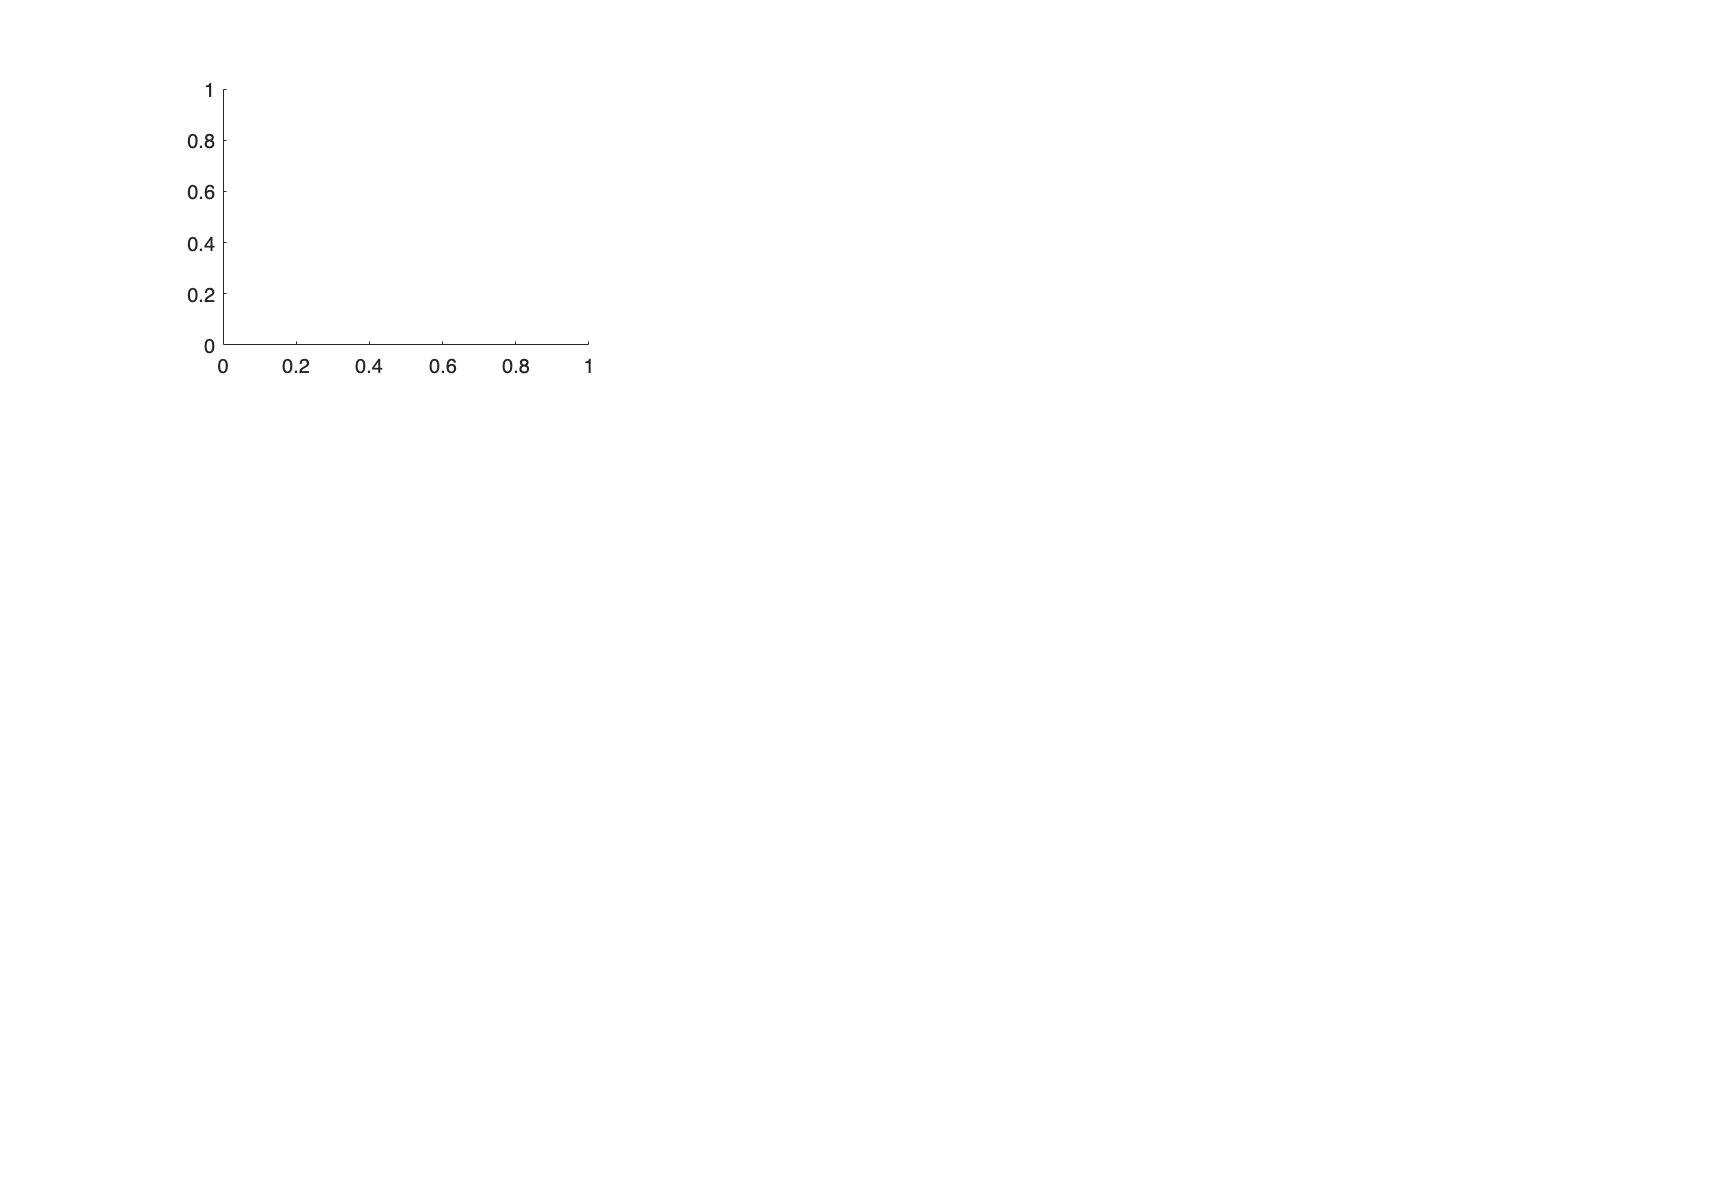

Unrecognized function or variable 'q'.

Error in KF (line 373)
            plot(q.time, rad2deg(q.signals.values(:, i)), 'LineWidth', 1.5);

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global kf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory_lkf.mat');
q_trajectory = q_trajectory_lkf;

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% Equilibrium
q_eq = q0;
pdot_eq = zeros(3*m, 1);
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
Delta_q0_deg = normrnd(zeros(n, 1), 2*ones(n, 1));
Delta_q0 = deg2rad(Delta_q0_deg);
% Q
Q1 = 1*10e-5 * diag(ones(n, 1)); 
Q2 = 1*10e-1 * diag(ones(n, 1)); 
Q = [Q1;
     Q2];
% R
R = 7.91e-06 * diag(ones(m*3, 1));
% Initial covariance
P0 = 0.1 * diag(ones(n, 1)); 
KF(Delta_q0, P0, q_eq, pdot_eq, Q, R, N_pdot, directory);

### Scenario 2 

Different values for  $\mathbf{R}_i = \sigma_{\mathbf{R}_i}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}$.

### 1.a --> $\sigma_{\mathbf{Q}}^2 = 10^{-1}\ rad^2$

### 1.b -->  $\sigma_{\mathbf{R}_1}^2 = 7.91\cdot10^{-7}\ m^2, \quad \sigma_{\mathbf{R}_2}^2 = 7.91\cdot10^{-5}\ m^2$

P_{k|k-1} tends to
    1.0002   -0.0001   -0.0000    0.0001    0.0002   -0.0001   -0.0001
   -0.0001    1.0001    0.0000   -0.0000   -0.0002    0.0001    0.0001
   -0.0000    0.0000    1.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0001   -0.0000   -0.0000    1.0001    0.0001   -0.0001   -0.0001
    0.0002   -0.0002   -0.0000    0.0001    1.0004   -0.0002   -0.0001
   -0.0001    0.0001    0.0000   -0.0001   -0.0002    1.0007    0.0001
   -0.0001    0.0001    0.0000   -0.0001   -0.0001    0.0001    1.0002

RMSE is
    0.4945

P_{k|k-1} tends to
    1.0160   -0.0099   -0.0012    0.0061    0.0199   -0.0043   -0.0078
   -0.0099    1.0069    0.0010   -0.0046   -0.0152    0.0063    0.0054
   -0.0012    0.0010    1.0008   -0.0020   -0.0025    0.0019    0.0015
    0.0061   -0.0046   -0.0020    1.0083    0.0112   -0.0097   -0.0111
    0.0199   -0.0152   -0.0025    0.0112    1.0384   -0.0202   -0.0122
   -0.0043    0.0063    0.0019   -0.0097   -0.0202    1.0615    0.0056
   -0.0078    0.00

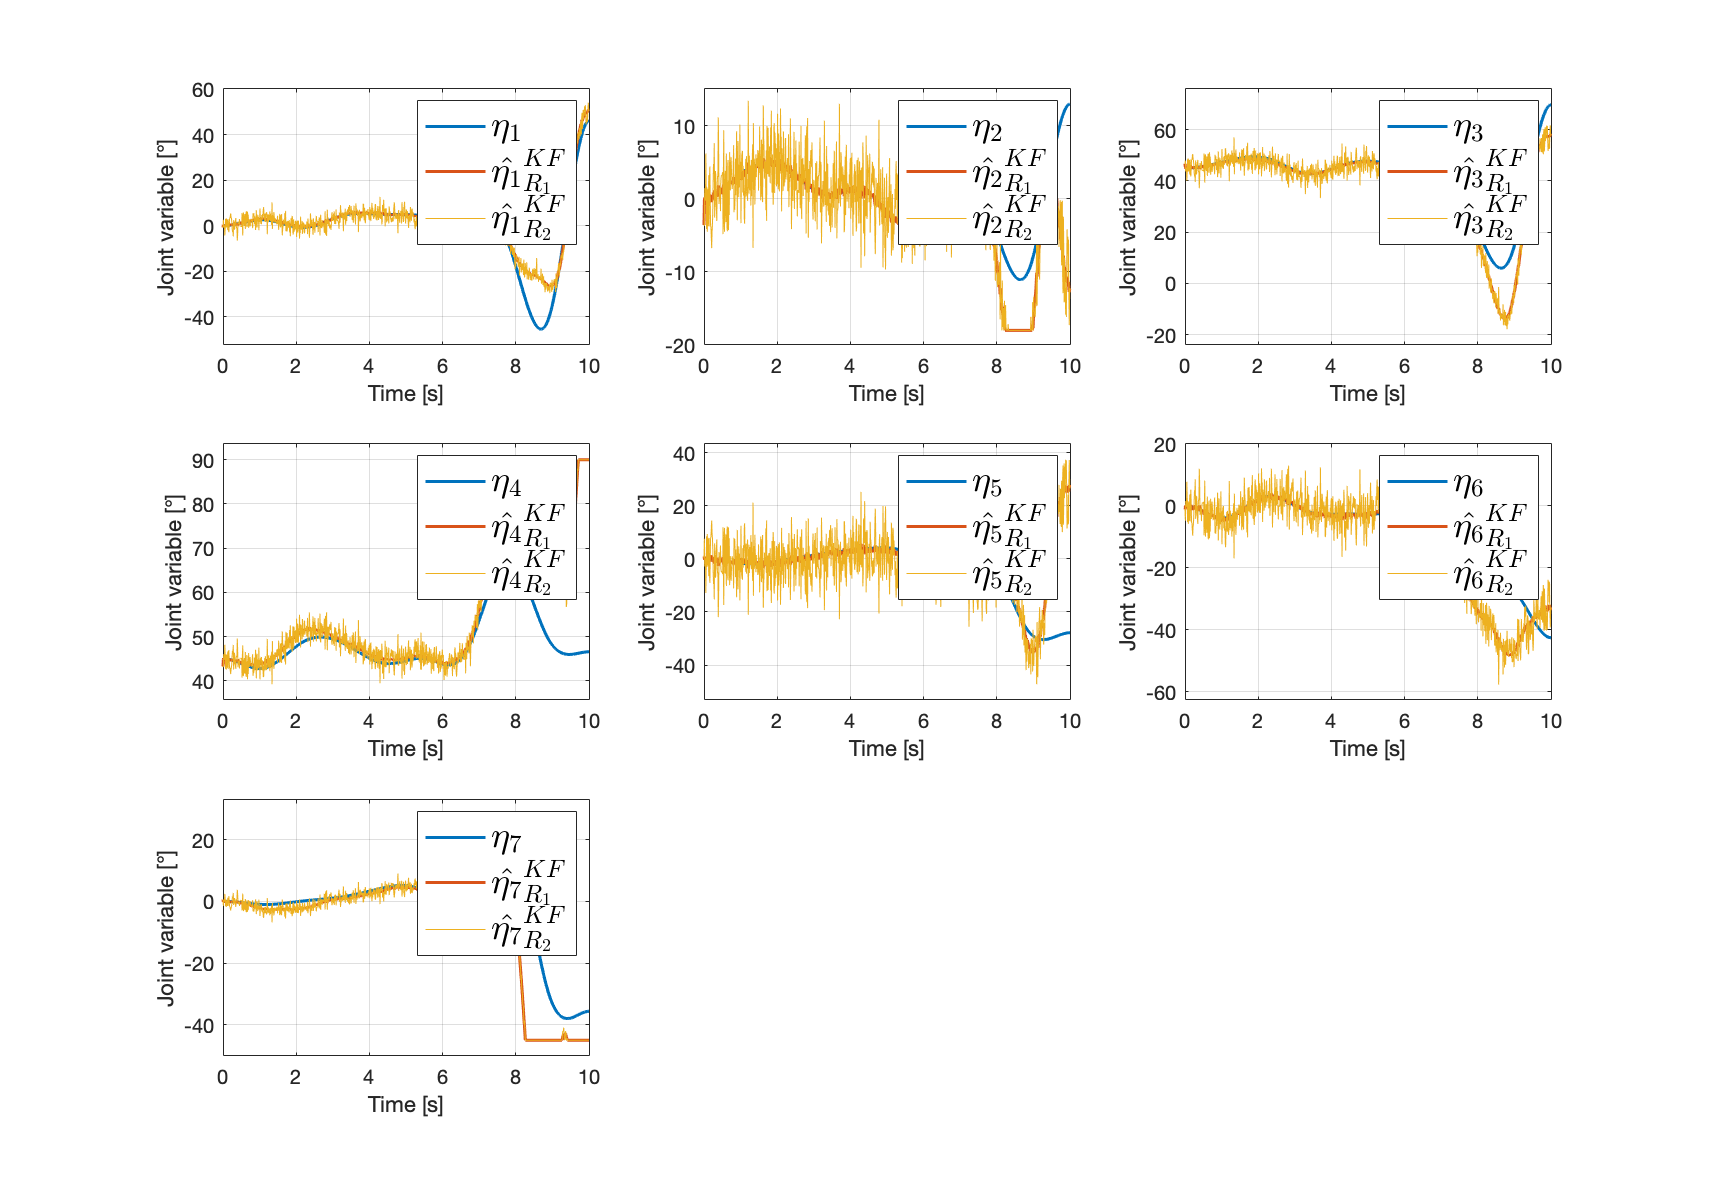

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global kf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory_lkf.mat');
q_trajectory = q_trajectory_lkf;

% Load markers
load('markers_best_6th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% Equilibrium
q_eq = q0;
pdot_eq = zeros(3*m, 1);
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
Delta_q0_deg = normrnd(zeros(n, 1), 2*ones(n, 1));
Delta_q0 = deg2rad(Delta_q0_deg);
% Q
Q = 1*10e-1 * diag(ones(n, 1)); 
% R
R1 = 7.91e-07 * diag(ones(m*3, 1));
R2 = 7.91e-05 * diag(ones(m*3, 1));
R = [R1;
     R2];
% Initial covariance
P0 = 0.1 * diag(ones(n, 1)); 
KF(Delta_q0, P0, q_eq, pdot_eq, Q, R, N_pdot, directory);

### $7^{th}$ Combination --> SINGULARITIES

### Scenario 3

### 1.a --> $\sigma_{\mathbf{Q}}^2 = 10^{-1}\ rad^2$

### 1.b -->  $\sigma_{\mathbf{R}}^2 = 7.91\cdot10^{-7}\ m^2$

STABILIZABLE
NOT DETECTABLE
P_{k|k-1} tends to
    0.0001   -0.0001   -0.0000    0.0000    0.0001   -0.0001   -0.0000
   -0.0001    0.0001    0.0000   -0.0000   -0.0001    0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0000   -0.0001
    0.0001   -0.0001   -0.0000    0.0000  136.1242  332.7616  -83.6660
   -0.0001    0.0000    0.0000   -0.0000  332.7616  813.4524 -204.5255
   -0.0000    0.0000    0.0000   -0.0001  -83.6660 -204.5255   51.4239

eigenvalues of F(I-KJ):
    1.0000
    0.0005
    0.0002
    0.0000
    0.0000
    0.0000

RMSE is
    1.2320



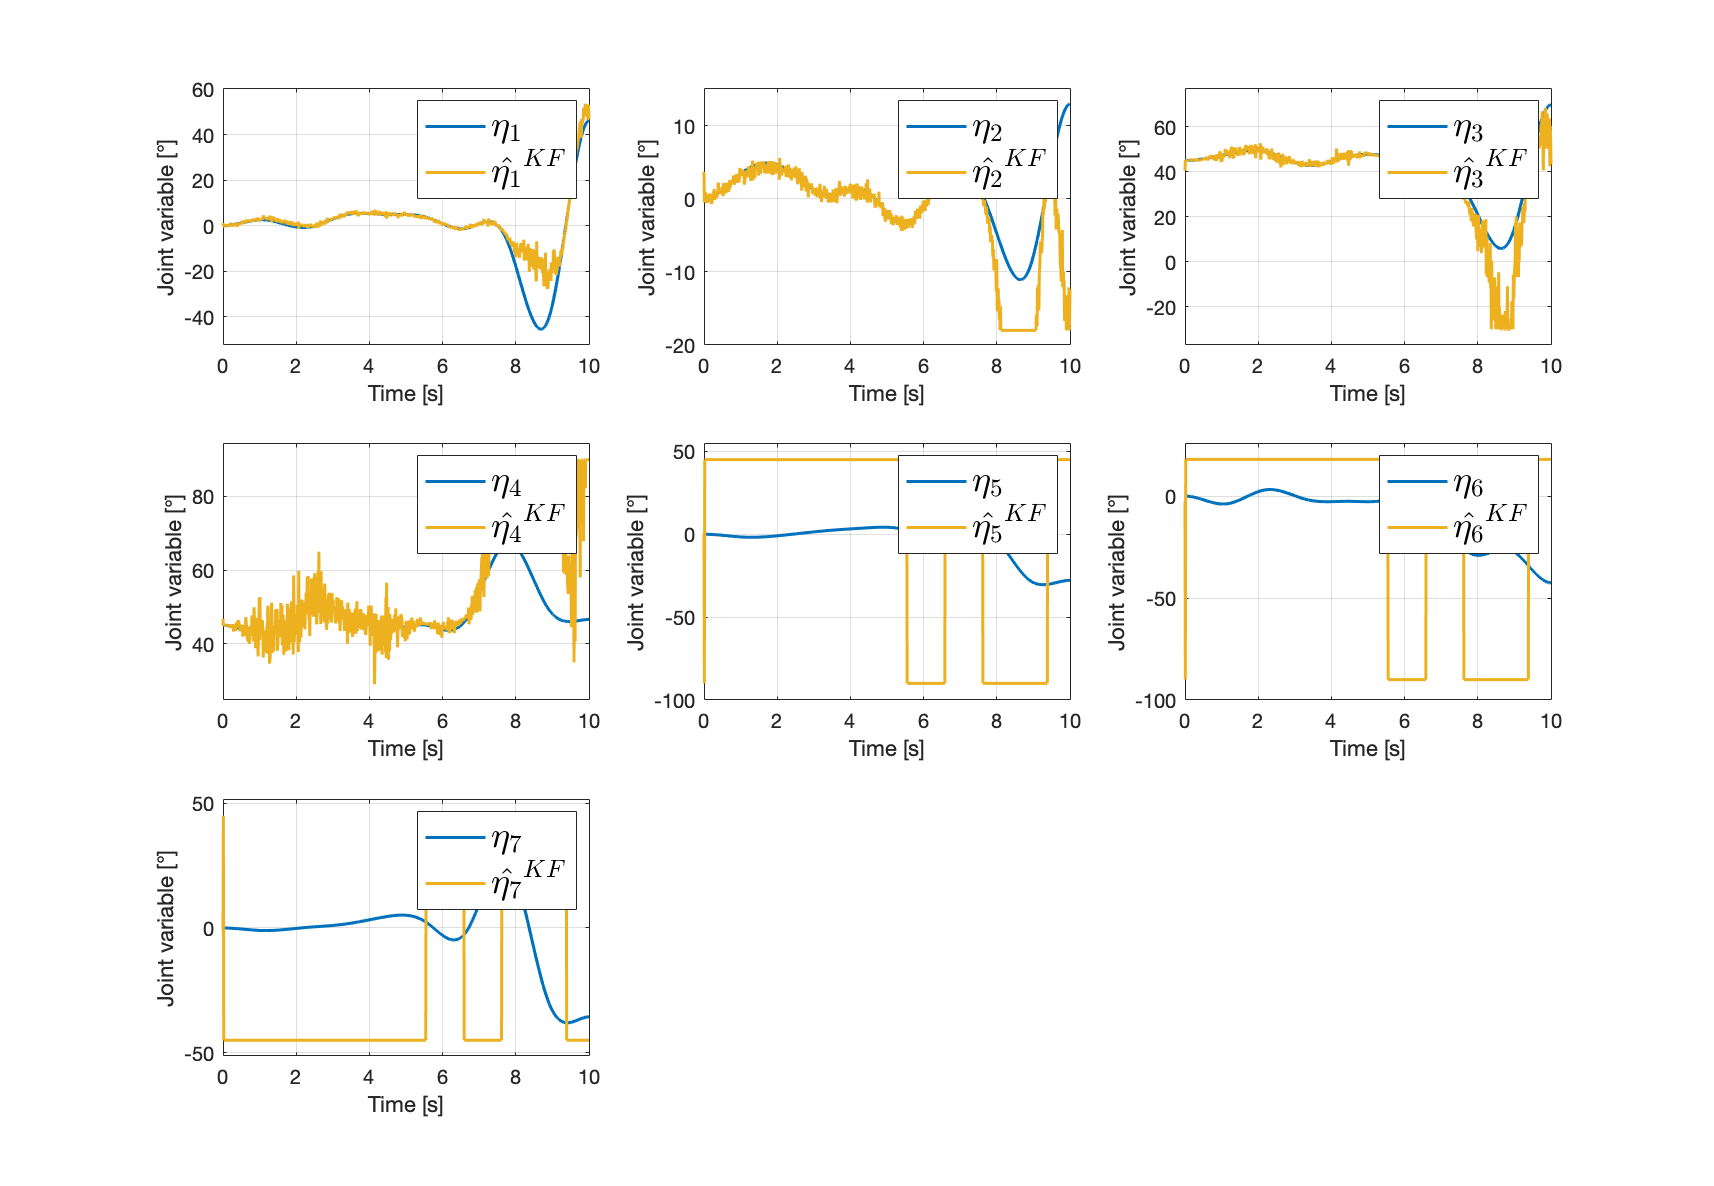

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global kf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory_lkf.mat');
q_trajectory = q_trajectory_lkf;

% Load markers
load('markers_best_7th.mat');
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2:3);
markers_hand = markers_best(:, 4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% Equilibrium
q_eq = q0;
pdot_eq = zeros(3*m, 1);
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
Delta_q0_deg = normrnd(zeros(n, 1), 2*ones(n, 1));
Delta_q0 = deg2rad(Delta_q0_deg);
% Q
Q = 1*10e-1 * diag(ones(n, 1)); 
% R
R = 7.91e-07 * diag(ones(m*3, 1));
% Initial covariance
P0 = 10e-1 * diag(ones(n, 1)); 
KF(Delta_q0, P0, q_eq, pdot_eq, Q, R, N_pdot, directory);

# EXTENDED KALMAN FILTER

In summary, the following steps are performed to compute the EKF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{\eta}_{k+1} = \textbf{f}(\mathbf{\eta}_{k}, \mathbf{u}_{k}) + \mathbf{w}_{k}  \\
\mathbf{p}_{k+1} = \mathbf{\Phi}(\mathbf{q}_{k+1}) + \mathbf{v}_{k+1} \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{\eta}}_{0\mid 0} = \mathbb{E}(\mathbf{\eta}_0) \quad, \quad
\mathbf{P}_{0\mid 0} = \mathbb{E}[(\mathbf{\eta}_0 - \hat{\mathbf{\eta}}_{0\mid 0})(\mathbf{\eta}_0 - \hat{\mathbf{\eta}}_{0\mid 0})^T]$ 

- For k = 0, 1, .. 

                          
$$\mathbf{F}_{k} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{\eta}}\right|_{\hat{\mathbf{\eta}}_{k\mid k},\mathbf{u}_{k}
$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_{k+1\mid k} = \mathbf{F}_{k}\mathbf{P}_{k\mid k}\mathbf{F}_{k}^T + \mathbf{Q} \\
\hat{\mathbf{\eta}}_{k+1\mid k} = \mathbf{f}(\hat{\mathbf{\eta}}_{k\mid k}, \mathbf{u}_{k})$$


                             
$$\mathbf{J}_{k+1} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{\eta}}\right|_{\hat{\mathbf{\eta}}_{k+1\mid k}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_{k+1} = \mathbf{P}_{k+1\mid k}\mathbf{J}_{k+1}^T(\mathbf{J}_{k+1}\mathbf{P}_{k+1\mid k}\mathbf{J}_{k+1}^T + \mathbf{R})^{-1}
\\
\mathbf{P}_{k+1\mid k+1} = (\mathbf{I} - \mathbf{K}_{k+1}\mathbf{J}_{k+1})\mathbf{P}_{k+1\mid k}(\mathbf{I} - \mathbf{K}_{k+1}\mathbf{J}_{k+1})^T+\mathbf{K}_{k+1}\mathbf{R}\mathbf{K}_{k+1}^T\\
\hat{\mathbf{\eta}}_{k+1\mid k+1} = \hat{\mathbf{\eta}}_{k+1\mid k} + \mathbf{K}_{k+1}[\textbf{p}_{k+1} - \mathbf{\Phi}(\hat{\mathbf{\eta}}_{k+1\mid k})]
$$


The values for $\hat{\mathbf{\eta}}_{0\mid 0}$, $\mathbf{P}_{0\mid 0}$, $\mathbf{Q}$, $\mathbf{R}$, $\mathbf{N_{\dot{p}}$ must be decided. 

- $\mathbf{N_{\dot{p}}} = 10^{-2}\cdot\sigma_{\dot{\mathbf{p}}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\dot{\mathbf{p}}}^2 = 0.0285\ \left(m/s\right)^2$.

- $\hat{\mathbf{\eta}}_{0\mid 0} \neq \mathbf 0$.

- $\mathbf{P}_{0\mid 0} = \sigma_{\mathbf{P}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\mathbf{P}}^2 = 0.1\ rad^2$.

In the following, 3 cases are analyzed. **Scenario 1**, **Scenario 2 **and** Scenario 3 **consider the $6^{th}$ combination.

**Scenario 4** consideres the $7^{th}$ combination.

## $6^{th}$ Combination --> NON-SINGULARITIES

### Scenario 1 

Different values for  $\mathbf{Q}_i = \sigma_{\mathbf{Q}_i}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}$.

### 1.a --> $\sigma_{\mathbf{Q}_1}^2 = 10^{-5}\ rad^2,\quad \sigma_{\mathbf{Q}_2}^2 = 0.1\ rad^2$

### 1.b -->  $\mathbf{R} = \sigma_{\mathbf{R}}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}, \quad \sigma_{\mathbf{R}}^2 = 7.91\cdot10^{-5}\ m^2$

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global ekf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
%arm.shoulder.length = 0.23; % [m]
%arm.forearm.length = 0.27; % [m]
markers_shoulder = markers_best(:, 1);
%markers_forearm = markers_best(:, 2);
markers_forearm = [];
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
q0_deg = normrnd(rad2deg(q0), 2*ones(n, 1));
q0 = deg2rad(q0_deg);
% Q
Q1 = 1*10e-5 * diag(ones(n, 1)); 
Q2 = 1*10e-1 * diag(ones(n, 1)); 
Qlist = [Q1;
         Q2];
% R
R = 7.91e-05 * diag(ones(m*3, 1));
Rlist = R;
% Initial covariance
P0 = 0.1 * diag(ones(n, 1)); 
EKF(q0, P0, Qlist, Rlist, N_pdot, directory);

Error using EKF
"from_mex" failed: Dimension mismatch. Expected 3-by-1, got 0-by-0 instead.
	Error in EKF.m (line 93)
		        output = sim('master_thesis_simulink.slx');
	Error in master_thesis.mlx (line 638)
	Error in 'master_thesis_simulink/System/EKF/Extended Kalman Filter' (line 114)

### Scenario 2 

Different values for  $\mathbf{R}_i = \sigma_{\mathbf{R}_i}^2\cdot\pmatrix{1 & \cdots & 0 \cr  \vdots& \ddots &\vdots \cr 0& \cdots& 1}$.

### 1.a --> $\sigma_{\mathbf{Q}}^2 = 10^{-1}\ rad^2$

### 1.b -->  $\sigma_{\mathbf{R}_1}^2 = 7.91\cdot10^{-7}\ m^2, \quad \sigma_{\mathbf{R}_2}^2 = 7.91\cdot10^{-5}\ m^2$

CASE 1 with Q = Q1 and R = R1
RMSE = 0.13105
CASE 2 with Q = Q1 and R = R2
RMSE = 0.40441


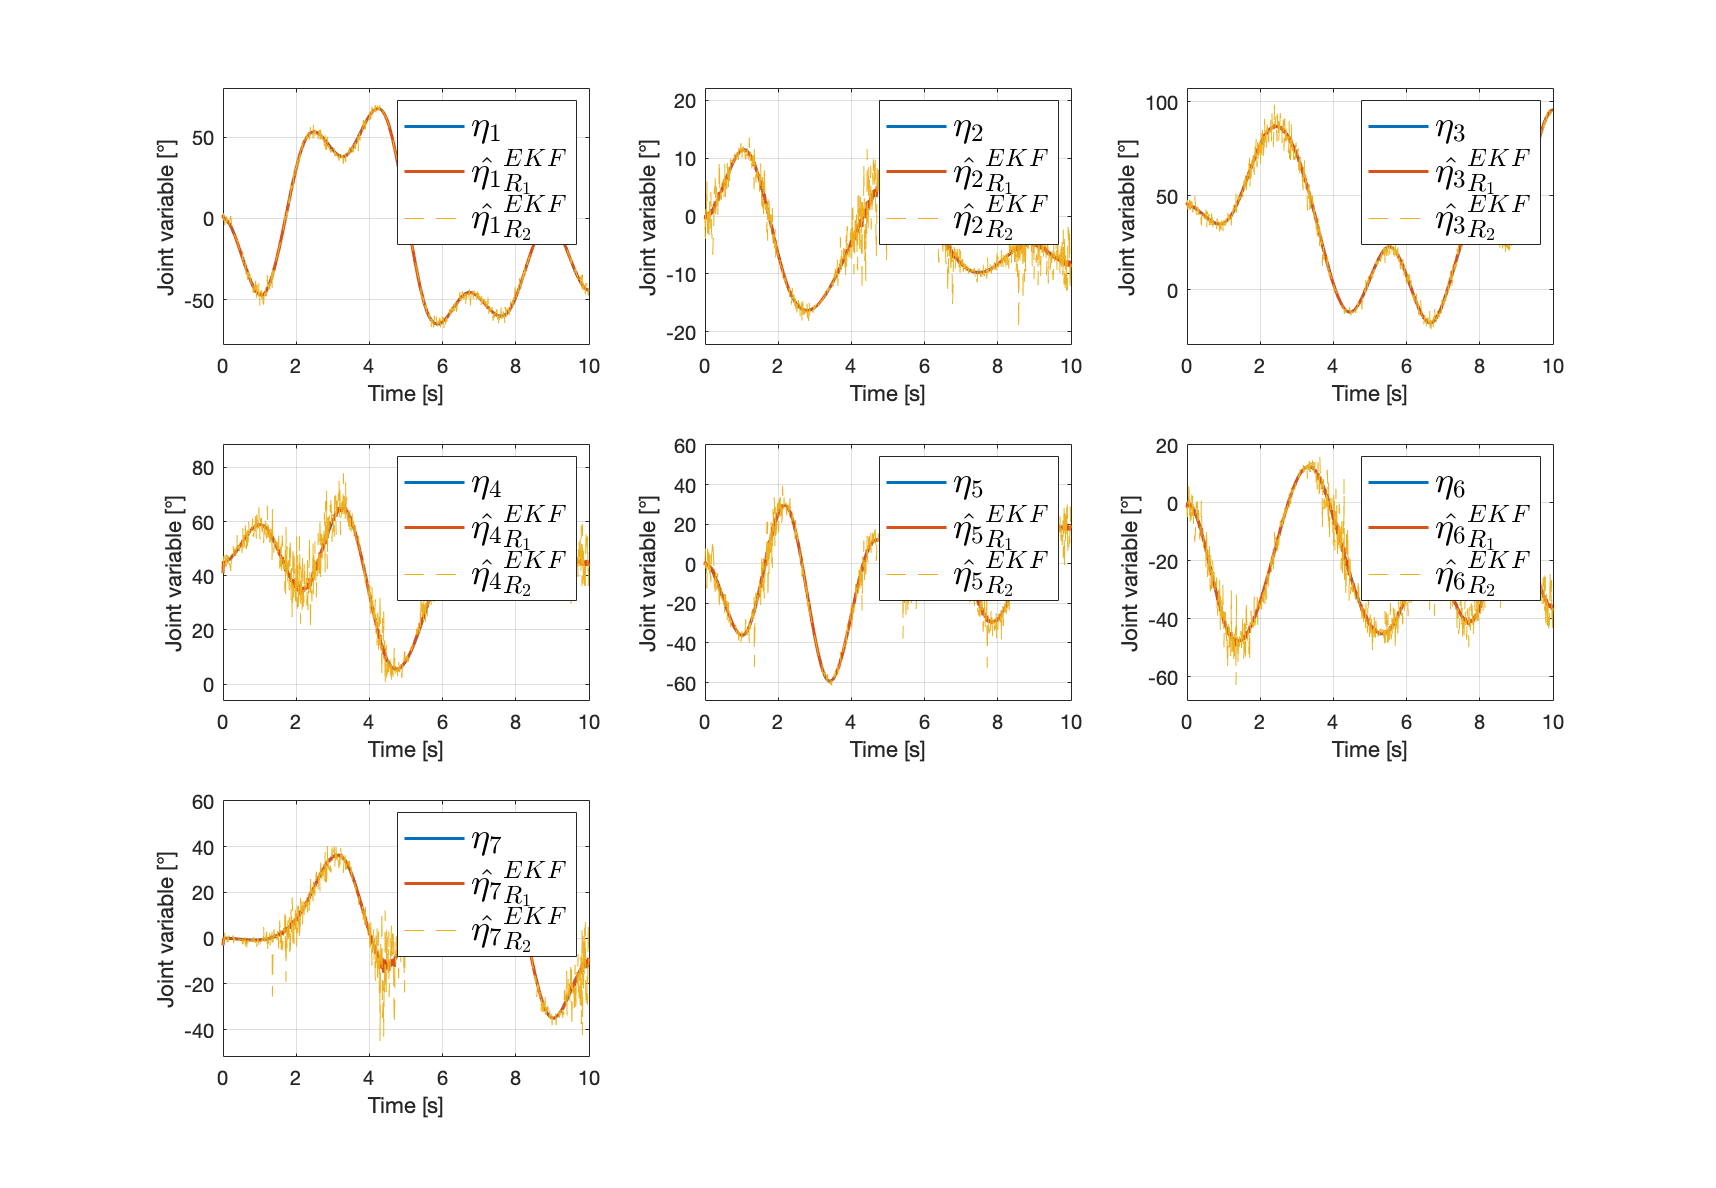

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global ekf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_6th.mat');
%arm.shoulder.length = 0.23; % [m]
%arm.forearm.length = 0.27; % [m]
markers_shoulder = markers_best(:, 1);
markers_forearm = markers_best(:, 2);
markers_hand = markers_best(:, 3:4);
m = size(markers_best, 2);
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(size(markers_shoulder, 2)), '_F', num2str(size(markers_forearm, 2)), '_H', num2str(size(markers_hand, 2)));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
q0_deg = normrnd(rad2deg(q0), 2*ones(n, 1));
q0 = deg2rad(q0_deg);
% Q
Q = 1*10e-1 * diag(ones(n, 1)); 
Qlist = Q;
% R
R1 = 7.91e-07 * diag(ones(m*3, 1));
R2 = 7.91e-05 * diag(ones(m*3, 1));
Rlist = [R1;
         R2];
% Initial covariance
P0 = 0.1 * diag(ones(n, 1)); 
EKF(q0, P0, Qlist, Rlist, N_pdot, directory);

### $7^{th}$ Combination --> SINGULARITIES

### Scenario 3 

### 1.a --> $\sigma_{\mathbf{Q}}^2 = 10^{-1}\ rad^2$

### 1.b -->  $\sigma_{\mathbf{R}_1}^2 = 7.91\cdot10^{-7}\ m^2, \quad \sigma_{\mathbf{R}_2}^2 = 7.91\cdot10^{-5}\ m^2$

% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global q0;
global ekf;
global noise;

% Run Human arm parameters
run('human_ar_p.m');

% Load trajectory
load('q_trajectory.mat');

% Load markers
load('markers_best_2nd.mat');
markers_shoulder = markers_best(:, 1);
shoulder_num = size(markers_shoulder, 2);
markers_forearm = [];
forearm_num = size(markers_forearm, 2);
markers_hand = markers_best(:, 2:3);
hand_num = size(markers_hand, 2);
m = shoulder_num + forearm_num + hand_num;
set_markers_simulink(markers_shoulder, markers_forearm, markers_hand);

% Sampling time
sample_Time = 0.01;

% Directory
directory = strcat('S', num2str(shoulder_num), '_F', num2str(forearm_num), '_H', num2str(hand_num));

% Simscape IC
q0 = q_trajectory.signals.values(1, :)';

%% Results
% N_pdot
N_pdot = 0.000285 * diag(ones(m*3, 1));
% Initial condition
q0_deg = normrnd(rad2deg(q0), 2*ones(n, 1));
q0 = deg2rad(q0_deg);
% Q
Q = 1*10e-1 * diag(ones(n, 1)); 
Qlist = Q;
% R
R = 7.91e-07 * diag(ones(m*3, 1));
Rlist = R;
% Initial covariance
P0 = 0.1 * diag(ones(n, 1)); 
save = false;
EKF(q0, P0, Qlist, Rlist, N_pdot, directory, save);

Error using EKF
Input must be a square matrix.
	Error in EKF.m (line 98)
		        output = sim('master_thesis_simulink.slx');
	Error in master_thesis.mlx (line 765)
	Error in 'master_thesis_simulink/System/EKF/Extended Kalman Filter' (line 101)

remove_blocks_simulink(markers_shoulder, markers_forearm, markers_hand);

# Experimental results

Firstly, for each experiment, the position of the markers $\mathbf{p}^{B}_{\mathbf{M}_i}, \quad i = 1,\dots,m,$ are computed. 


$$\mathbf{p}^{B} = \pmatrix{\mathbf{p}^{B}_{\mathbf{M}_1}  \cr  \vdots\cr \mathbf{p}^{B}_{\mathbf{M}_m}}$$


## $\mathbf{Q}$ tuning

$\mathbf Q$ for LKF and EKF is tuned properly in the following. Among the matrices in a list for $\mathbf Q$, $\hat{\mathbf Q}$ is the one


$$\hat{\mathbf{Q}}^{EKF} = \underset{\mathbf{Q}\in \mathcal{L_{\mathbf{Q}}}}{argmin}\frac{1}{M}\sum_{i=1}^{M}\frac{1}{S_i}\sum_{j = 1}^{S_i}\frac{1}{N_{i,j}}\sum_{k=1}^{N_{i,j}}\left\|\mathbf{p}^{0^\prime}_{6, i, j}\left(t_k\right)-\mathbf{\Phi}\left(\hat{\mathbf{\eta}}^{EKF\left(\mathbf{Q}\right)}\left(t_k\right), \mathbf{p}^B_{6, i,j}\right) \right\|^2$$


% Clear variabless
clear all;
clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global kf ekf noise;
global p_0p v_0p;

% Run Human arm parameters
run('human_ar_p.m');

% Sampling time
sample_Time = 0.01;

%%%
%%% EKF IC
%%%
ekf.q0 = 0 * ones(n, 1);
ekf.P0 = diag(ones(n, 1));

% Directory list
directory_list = ['S0_F1_H2';
                  'S1_F0_H2';
                  'S0_F2_H2';
                  'S1_F0_H3';
                  'S1_F1_H2';
                  'S2_F0_H2';
                  'S1_F2_H2'];

%%%
%%% Markers_pos list
markers_num_list = [1;1;1;1;1;1;1];

% Sim_num list
sim_num_list = [3;3;3;3;3;3;3]; 

% Q list
Q_list = [0.001;
          0.01;
          0.1;
          1;
          10;
          100;
          1000];
% R list
R_list = [0.01;
          0.1;
          1;
          10;
          100;
          1000;
          10000];

% Run function
[Q_best, R_best] = Q_tuning(directory_list, markers_num_list, sim_num_list, Q_list, R_list);

## Least Squares (LS)

% Clear variabless
clear all;

Set of markers: SHOULDER: 0, FOREARM: 1, HAND: 2
Q: 1, R: 1
Q: 1, R: 2
Q: 1, R: 3
Q: 1, R: 4
Q: 1, R: 5
Q: 1, R: 6
Q: 1, R: 7
Q: 2, R: 1


Q: 2, R: 2
Q: 2, R: 3
Q: 2, R: 4
Q: 2, R: 5
Q: 2, R: 6
Q: 2, R: 7
Q: 3, R: 1
Q: 3, R: 2


Q: 3, R: 3
Q: 3, R: 4
Q: 3, R: 5
Q: 3, R: 6
Q: 3, R: 7
Q: 4, R: 1


Q: 4, R: 2


Q: 4, R: 3
Q: 4, R: 4


Q: 4, R: 5
Q: 4, R: 6
Q: 4, R: 7
Q: 5, R: 1
Q: 5, R: 2
Q: 5, R: 3


Q: 5, R: 4


Q: 5, R: 5


Q: 5, R: 6
Q: 5, R: 7
Q: 6, R: 1


Q: 6, R: 2


Q: 6, R: 3
Q: 6, R: 4


Q: 6, R: 5
Q: 6, R: 6
Q: 6, R: 7
Q: 7, R: 1
Q: 7, R: 2


Q: 7, R: 3


Q: 7, R: 4
Q: 7, R: 5
Q: 7, R: 6
Q: 7, R: 7
RMSE of DIR: S0_F1_H2
   1.0e+03 *

    0.0002    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002
    1.0000    0.0003    0.0001    0.0000    0.0000    0.0001    0.0002
    0.0003    0.0003    0.0003    0.0003    0.0000    0.0000    0.0001
    0.0003    1.0000    0.0003    1.0000    0.0001    0.0000    0.0000
    0.0003    0.0003    1.0000    0.0003    1.0000    0.0000    0.0000
    1.0000    1.0000    0.0003    1.0000    0.0003    0.0002    0.0001
    0.0003    1.0000    0.0003    0.0003    0.0003    0.0003    0.0002

Set of markers: SHOULDER: 1, FOREARM: 0, HAND: 2
Q: 1, R: 1


clear global;
close all;
clc;

% Global variables
global markers_shoulder markers_forearm markers_hand;
global kf ekf noise;
global p_0p v_0p;

% Run Human arm parameters
run('human_ar_p.m');

% Sampling time
sample_Time = 0.01;

% Folders
simulations_folders = ['S0_F1_H2';
                       'S1_F0_H2';
                       'S0_F2_H2';
                       'S1_F0_H3';
                       'S1_F1_H2';
                       'S2_F0_H2';
                       'S1_F2_H2'];
%%%
%%%  Directory
%%%
num_dir = 7;
directory = simulations_folders(num_dir, :);
m = str2num(directory(2)) + str2num(directory(5)) +  str2num(directory(8));

%%%
%%% LS IC
%%%
LS.q0 = deg2rad(0 * ones(n, 1));

## Kalman Filter (KF)

%%%
%%% KF equilibrium point {q_eq, pdot_eq}
%%%
kf.q_eq = 0 * ones(n, 1);
kf.pdot_eq = 0 * ones(3*m, 1);

%%%
%%% KF IC
%%%
kf.Delta_q0 = 0 * ones(n, 1);
kf.P0 = diag(ones(n, 1));

## Extended Kalman Filter (EKF)

%%%
%%% EKF IC
%%%
ekf.q0 = 0 * ones(n, 1);
ekf.P0 = diag(ones(n, 1));

## Show Results

markers_num_list = [1];
sim_num_list = [4]; 
load('Q_best.mat');
load('R_best.mat');
Q_best = Q_best(num_dir);
R_best = R_best(num_dir);
show_results(directory, markers_num_list, sim_num_list, Q_best, R_best, 2, true);

# Experimental problem

One simulation is run in order to estimate $t_{Sh}^{0, 0Conf}$ (the position of the shoulder wrt Super marker 0 when ARM IS AT 0 CONFIGURATION) necessary for the mex functions generation. This first estimate is then used to compute $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$(the position of the markers wrt corresponding Bases RF).

## Position of the shoulder wrt Super marker 0 when ARM IS AT 0 CONFIGURATION

run('parameters_tuning.m');

Only f_Phi and f_J are generated with $t_{Sh}^{0, 0Conf}$ since only these functions are needed to compute the position and velocity of the markers wrt corresponding Bases RF.

## Mex functions generation

% Clear variables
clear;
clear global;
close all;  
clc;

% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run human_arm_parameters
run('human_arm_parameters.m');

% tSh_0, 0 Configuration
tSh_0_0Conf = [0.01; -0.229; -0.261];

% Generate mex files
mex_generation_Experiments(arm.markers.links, sample_Time, tSh_0_0Conf, 'true', 'true');

$t_{Sh}^{0, 0Conf}$is used to compute $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$ when arm is at 0 configuration and these estimates are then used to compare the position measurement of the markers and FK function evaluated at q = 0.

% Clear variables
clear;
clear global;
close all;  
clc;
% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run model_validation
run('model_validation.m');

Now that the model is validated,  $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$ will be used in the following (markers' positions are constant wrt Bases RF of each link). However, new mex functions will be generated using a different position of the Shoulder wrt Super marker 0, $t_{Sh}^{0, Robust}$ which is an average of different Shoulder positions since it slightly moves when the arm moves.

## Position of the shoulder wrt Super marker 0 when ARM IS MOVING

run('parameters_tuning.m');

Mex functions are generated with $t_{Sh}^{0, Robust}$.

## Mex functions generation

% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run human_arm_parameters
run('human_arm_parameters.m');

% tSh_0, Robust
tSh_0_Robust = [0.03; -0.246; -0.32];

% Generate mex files
mex_generation_Experiments(arm.markers.links, sample_Time, tSh_0_Robust, 'false', 'true');

## Noise estimation Rp, Rv ---> R = Rp,  Qk = Gk*Rv*Gk' (K < N) (N is a parameter)

R is the covariance matrix of the markers' position noise.

run('R_estimation.m'); 

% Add path of the Experiments folder
addpath('Scripts/');
addpath('Functions/');
addpath('Scripts/Experiments/');
addpath('Functions/Experiments/');
% Run model_validation
run('model_validation.m');

## Experimental results

Use Model validation to compute  $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$.

After, the function is run to compute the estimates.

% Run Human arm aparameters
run('human_arm_parameters_exp.m')

% Load Noise and Markers
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_shoulder.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_forearm.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_hand.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/noise.mat'));

## LS

%%%
%%% LS Initial estimate
%%%
q0_LS = zeros(7, 1);

## EKF

%%%
%%% EKF Initial estimate q0
%%%
ekf.q0 = zeros(7, 1);

%%%
%%% EKF Initial Covariance P0
%%%
ekf.P0 = diag(ones(7, 1));

## Choose method

% Run function

%%%
%%% Simulation time
%%%
simulink.time = 40;

%%%
%%% Choose method
%%%
method_flag = "EKF";
out = LS_KF_EKF_exp(method_flag, directory);
% Save variables
p_0p = out.p_0p;
v_0p = out.v_0p;
marker_case = 6; 
sim_num = 1;
save(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_', num2str(marker_case), '/Sim_', num2str(sim_num), '/p_0p.mat'), 'p_0p');
save(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_', num2str(marker_case), '/Sim_', num2str(sim_num), '/v_0p.mat'), 'v_0p');
clear marker_case sim_num p_0p v_0p;

ekf.q0 = zeros(7, 1);
ekf.P0 = diag([1;1;1;1;1;1;1]);
noise.Q = diag([0.1 0.1 0.1 0.1 0.01 0.01 0.01]);
noise.R = noise.Rp * 9000;